# Lab 2 -- Using Statistical Functions and  Histograms in MATLAB

#### Lab Section ____________

#### Team Members

#### _____________________

#### _____________________

#### _____________________

_______________________   

### Team Lead

_______________________

### **Objective:**

The objective of this activity is to gain experience using the statistical functions in MATLAB to process digital signals. 

###  **Intended Learning Outcomes: **

- Be able to use statistical functions in MATLAB to analyze data 

- Become familiar with using MATLAB commands: rand, max, min, mean, std 

- Use the histogram function to estimate and characterize the probability density function of random variable

- Analyze a dataset in terms of its signal to noise ratio

- Analyze the histogram of quantization noise for large and small signals relative to the quantization step size

### Procedure:

Follow the steps in each section of the Live script running each block as you go.  Be sure to answer the questions posed. You can answer these right in the text sections themselves.  You will submit your completed document as a MATLAB Live Script file and as an PDF file when you are completed. You will also submit a WBR - Work Breakdown Report.

## Part 1 - Using Lab2_Chapter2_Section1 Dataset (Simple Stats - 15 Points)

Load the matlab datafile from myCourses "Lab2_Chapter2_Section1.mat" .  This will load two variables into the work space, 'sample' and 'signal'

clear
load Lab2_Chapter2_Section1.mat

Error using load
Unable to read file 'Lab2_Chapter2_Section1.mat'. No such file or directory.

[sample, signal]

Press the Button below to Run the code in this section

### Step 1 Compute the Statistics

This file contains a variable called signal that has 730 samples.  Compute the maximum value (max), minimum value (min), average value (mean), standard deviation (std) and the variance ( square of the standard deviation) of the variable 'signal'. 

%  Create the variables below that represent the statistics of the variable signal
%
%  maxSignal =
%  minSignal =
%  avgSignal =
%  stdSignal =
%  varSignal =

%  Solution -- Place your code here
maxSignal = max(signal)

maxSignal = 76.4106

minSignal = min(signal)

minSignal = 20.4169

avgSignal = mean(signal)

avgSignal = 48.1501

stdSignal = std(signal)

stdSignal = 8.3260

varSignal = sqrt(stdSignal)

varSignal = 2.8855

Press the Button below to Run your code in this section

### Step 2  Create a Data Table

Create a table in MATLAB to display the values.  Use the 'table' function in MATLAB.   I've created the first table for you.  You can use this as a template to create later tables.  Use the help feature of MATLAB to look up how to enter values in a table.  The values of a column must be a column vector.  Use the Properties 'RowName' and 'VariableNames' to add row names and column names respectively.  Note that the list of row names and variable names must be a MATLAB cell array which is a data type that is enclosed by curly braces.  For example a = { 'first', 'second', 'third'} is a cell array.

% Create a column vector with the values for the table.
% Each value for the statistics is in one row

valuesForTable = [maxSignal; minSignal; avgSignal; stdSignal; varSignal];

%  Create the table.  Add Row Names and a Name for the column of values

statsTable = table(valuesForTable,...
    'RowNames',{'Maximum','Minimum','Average','Standard Deviation','Variance'},...
    'VariableNames',{'Values'})

statsTable = 5×1 table
                          Values
                          ______

    Maximum               76.411
    Minimum               20.417
    Average                48.15
    Standard Deviation     8.326
    Variance              2.8855


Press the Button below to Run the code in this section

### Step 3  Plot the Data

Plot the values of the varible 'signal' versus the variable 'sample'.  I have made the first plot for you.  Add a descriptive title,  and label the x-axis and the y-axis appropriately using the MATLAB commands 'title', 'xlabel' and 'ylabel' appropriately.  Turn on the grid

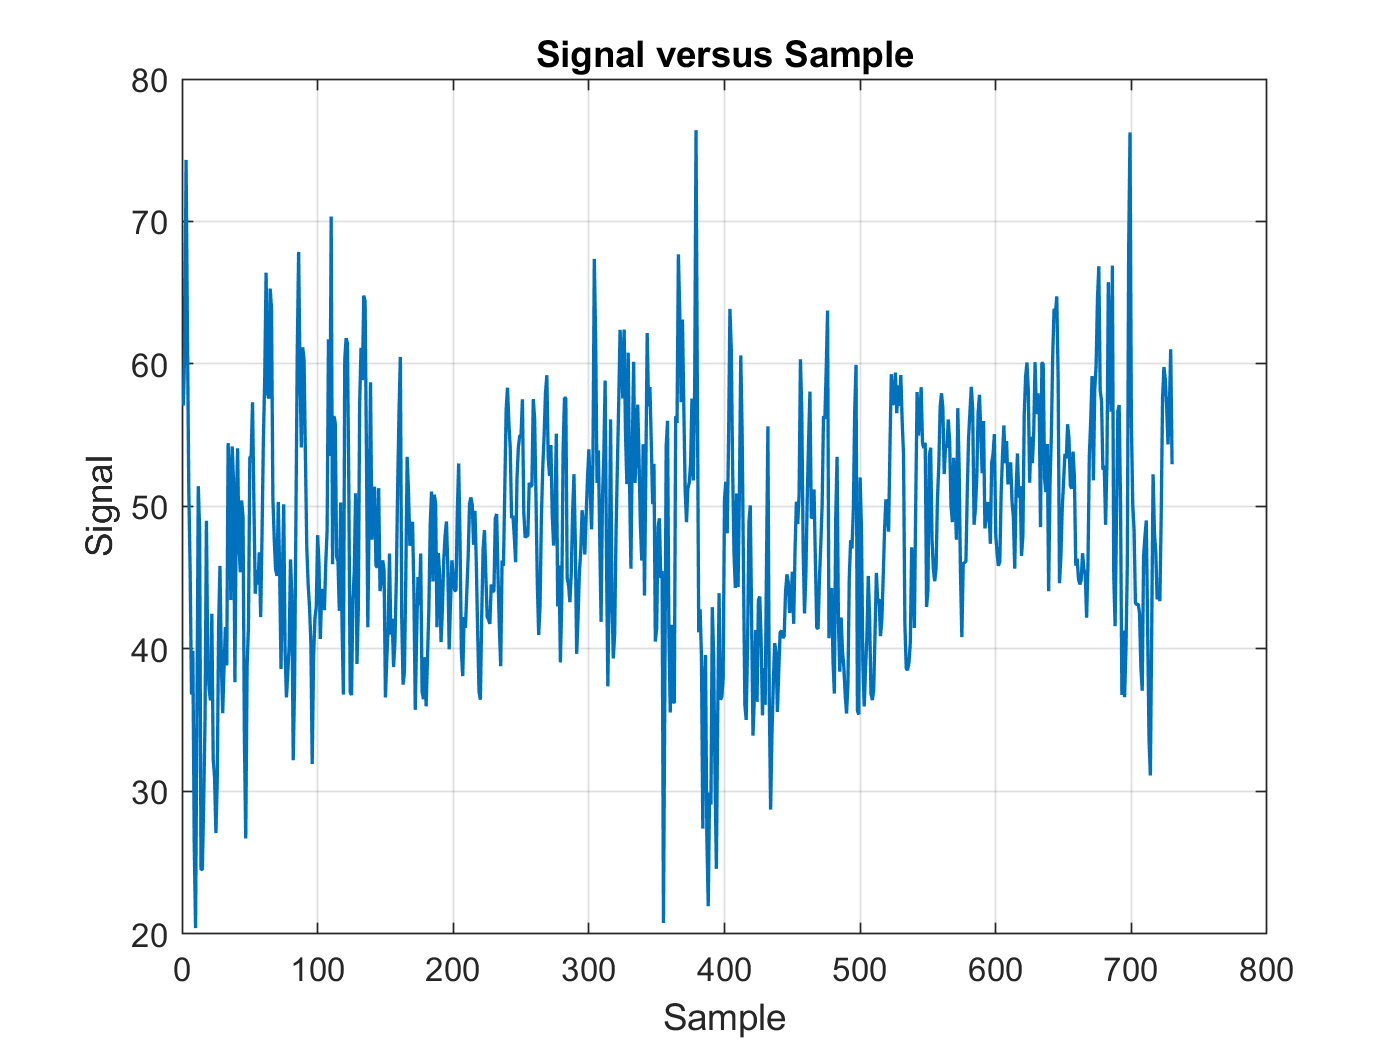

%  Plot the variable signal versus the variable sample.  Use the default line colors and style (blue and - )Use a larger
%  linewidth and turn on the grid


%  Solution -- Place your code to label the axes and title the graph
figure
plot( sample, signal, 'LineWidth',1 )
grid on
title('Signal versus Sample')
xlabel('Sample')
ylabel('Signal')

Press the Button below to Run the code in this section

### Question 1

Anwer the following questions by typing directly in the text section of this Live Script.

Which statistical parameters can you estimate by just observing the samples on the graph?  Which ones can you not estimate?  Do the values that you estimate by observing the graph agree with the values that you computed?  Why or why not?

### Type your answer here:

By observing the graph, I can estimate the mean (average), minmum and maxmim of the signal, and roughly extreme signal values (statistical outiers). Everythng that was listed above does agree with cacuated values. However, it is har for me just by looking at graph to estimated std. deviation and, thus, variance.

### Step 4  Create a Histogram

MATLAB has a function to create histograms of the data, 'histogram(y)'.  Use the MATLAB HELP to find more details on the function.

Use the MATLAB histogram function to plot the histogram of the signal.  Add a title, and label the x and y axes of the plot

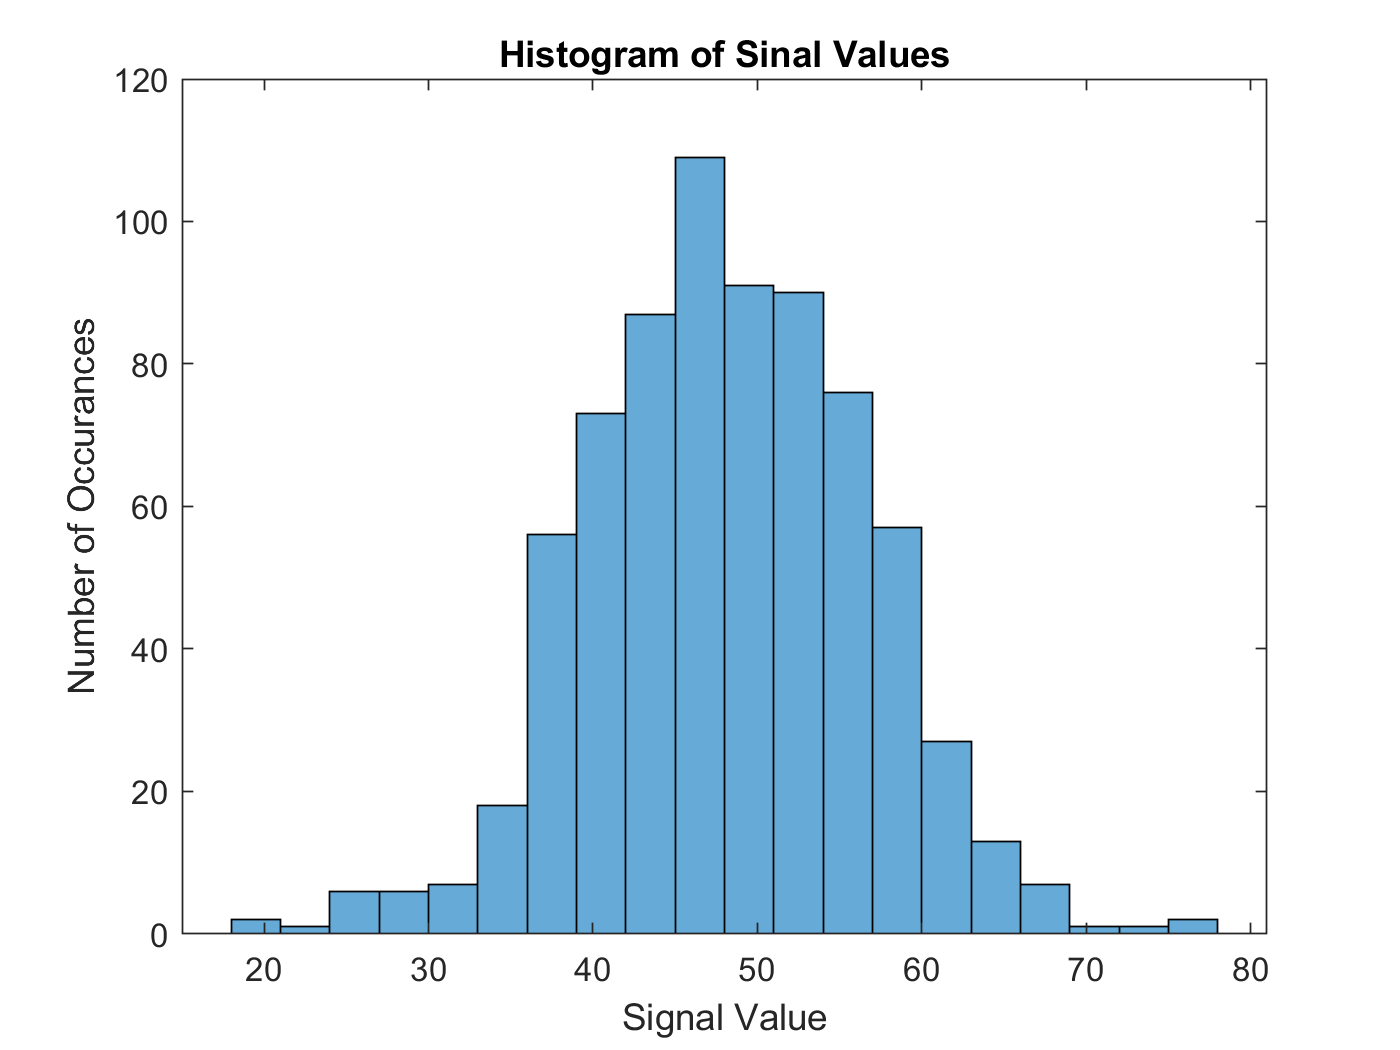

%  Plot a histogram of the signal data.


%  Solution -- Place your code 
histogram(signal)
title('Histogram of Sinal Values')
xlabel('Signal Value')
ylabel('Number of Occurances')

  Press the Button below to Run the code in this section

#### Question 2

What probability distribution best describes the data (uniform, triangular, normal, other)?  Type your answer below and explain.

#### Type your answer here:

Bell-shaped uniform normal distribution.

## Part 2  Using Lab2_Chapter2_Section2 Dataset (Sum of RV - 15 Points)

Load the matlab datafile from myCourses "Lab2_Chapter2_Section2.mat" .  This will load four variables into the work space, 'sample' and 'signal_1', 'signal_2', 'sumSignals'

%  Clear the workspace and load the data file
clear
load Lab2_Chapter2_Section2.mat
[sample, signal_1, signal_2, sumSignals]

ans =     1.0000   80.1875    3.9687   84.1562
    2.0000   79.6697    3.9136   83.5833
    3.0000   79.6080    3.1394   82.7475
    4.0000   80.4404    5.2124   85.6528
    5.0000   80.3575   11.4475   91.8049
    6.0000   80.2005    5.0002   85.2007
    7.0000   79.9836    3.8574   83.8410
    8.0000   79.5035    3.4783   82.9818
    9.0000   79.9984    6.2141   86.2125
   10.0000   80.1172    9.2031   89.3204


Press the Button below to Run the code in this section

### Step 1 Compute the Statistics

This file contains three variables.  The variables 'signal_1' and 'signal_2' have 730 samples each.  The variable 'sum_signals' is the sum of those two signals.  Compute the maximum value (max), minimum value (min), average value (mean), standard deviation (std) and the variance ( square of the standard deviation) of the variable 'signal_1'.  Repeat these calculations for signal 2.  Also, compute the same statistics for the variable sumSignals that is the sum of signal_1 and signal_2.

%  Create the variables below that represent the statistics of the variable signal
%
%  maxSignal_1 =
%  minSignal_1 =
%  avgSignal_1 =
%  stdSignal_1 =
%  varSignal_1 
%
%  Create another set for signal_2 and for the sum of the signals

%  Solution -- Place your code here
maxSignal_1 = max(signal_1)

maxSignal_1 = 80.4993

minSignal_1 = min(signal_1)

minSignal_1 = 79.5003

avgSignal_1 = mean(signal_1)

avgSignal_1 = 80.0081

stdSignal_1 = std(signal_1)

stdSignal_1 = 0.2885

varSignal_1 = sqrt(stdSignal_1)

varSignal_1 = 0.5371


maxSignal_2 = max(signal_2)

maxSignal_2 = 12.9890

minSignal_2 = min(signal_2)

minSignal_2 = 3.0090

avgSignal_2 = mean(signal_2)

avgSignal_2 = 7.9344

stdSignal_2 = std(signal_2)

stdSignal_2 = 2.9450

varSignal_2 = sqrt(stdSignal_2)

varSignal_2 = 1.7161


signalSum = signal_1 + signal_2

signalSum =    84.1562
   83.5833
   82.7475
   85.6528
   91.8049
   85.2007
   83.8410
   82.9818
   86.2125
   89.3204


maxSignalSum = max(signalSum)

maxSignalSum = 93.4239

minSignalSum = min(signalSum)

minSignalSum = 82.6443

avgSignalSum = mean(signalSum)

avgSignalSum = 87.9425

stdSignalSum = std(signalSum)

stdSignalSum = 2.9674

varSignalSum = sqrt(stdSignalSum)

varSignalSum = 1.7226

Press the Button below to Run your code in this section

### Step 2  Create a Data Table

Create a table in MATLAB to display the computed statistics.  Use the code from the previous section as a template.  Copy, Paste and modify the code as needed.  Create a table that looks like the table in the figure below:

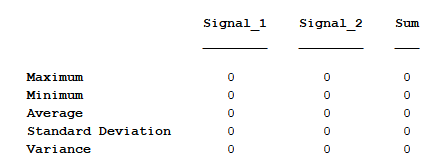

Use the 'table' function in MATLAB.   I've created the first column vector for you.  Create the other two.

% Create a column vector with the values for the table.
% Each value for the statistics is in one row

valSig1 = [maxSignal_1; minSignal_1; avgSignal_1; stdSignal_1; varSignal_1];
% Remove the comments and complete the two lines of code below
valSig2 = [maxSignal_2; minSignal_2; avgSignal_2; stdSignal_2; varSignal_2]

valSig2 =    12.9890
    3.0090
    7.9344
    2.9450
    1.7161


valSum = valSig1 + valSig2

valSum =    93.4883
   82.5093
   87.9425
    3.2335
    2.2532




%  Create the table.  Adds Row Names and a Name for the column of values

statsTable = table(valSig1, valSig2, valSum,...
    'RowNames',{'Maximum','Minimum','Average','Standard Deviation','Variance'},...
    'VariableNames',{'Signal_1', 'Signal_2','Sum'})

statsTable = 5×3 table
                          Signal_1    Signal_2     Sum  
                          ________    ________    ______

    Maximum                80.499      12.989     93.488
    Minimum                  79.5       3.009     82.509
    Average                80.008      7.9344     87.943
    Standard Deviation     0.2885       2.945     3.2335
    Variance              0.53713      1.7161     2.2532


Press the Button below to Run the code in this section

### Step 3  Plot the Data

Create an individual plot of each variable signal_1, signal_2 and sumSignal.  Properly label the title and the axes in each case.  Scale the y-axes for all three graphs from 0 to 100 using the 'ylim' function.  For example ylim( [yMIn,yMax] ) where yMin and yMax are the minimum and maximum y-values.  Using the same axes (scale) for graphs that you are going to compare is very helpful to the reader.  Turn the grid on for all three graphs.  Use the plotting code from previous sections as a starting point.  Copy and Paste as needed.  Create a new figure for each plot.

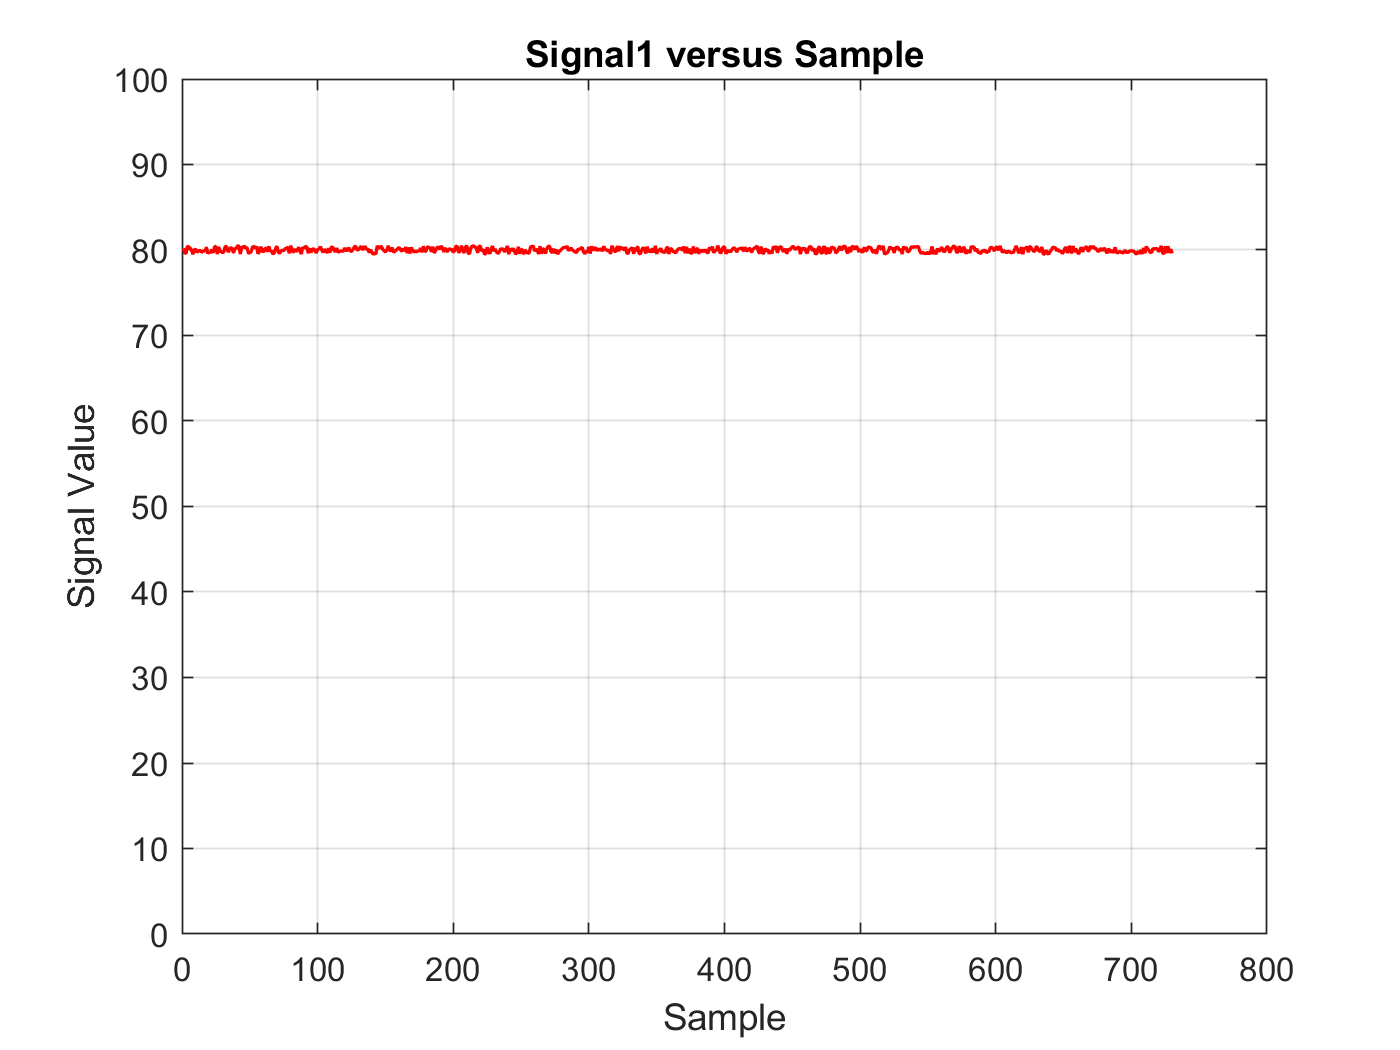

%  Plot the variables versus the variable sample.  Use the default line colors and style (blue and - )Use a larger
%  linewidth and turn on the grid

%  Solution -- Place your code to label the axes and title the graph

%  Signal 1
figure
plot( sample, signal_1,'red','LineWidth',1)
grid on
ylim([0,100])
title('Signal1 versus Sample')
xlabel('Sample')
ylabel('Signal Value')

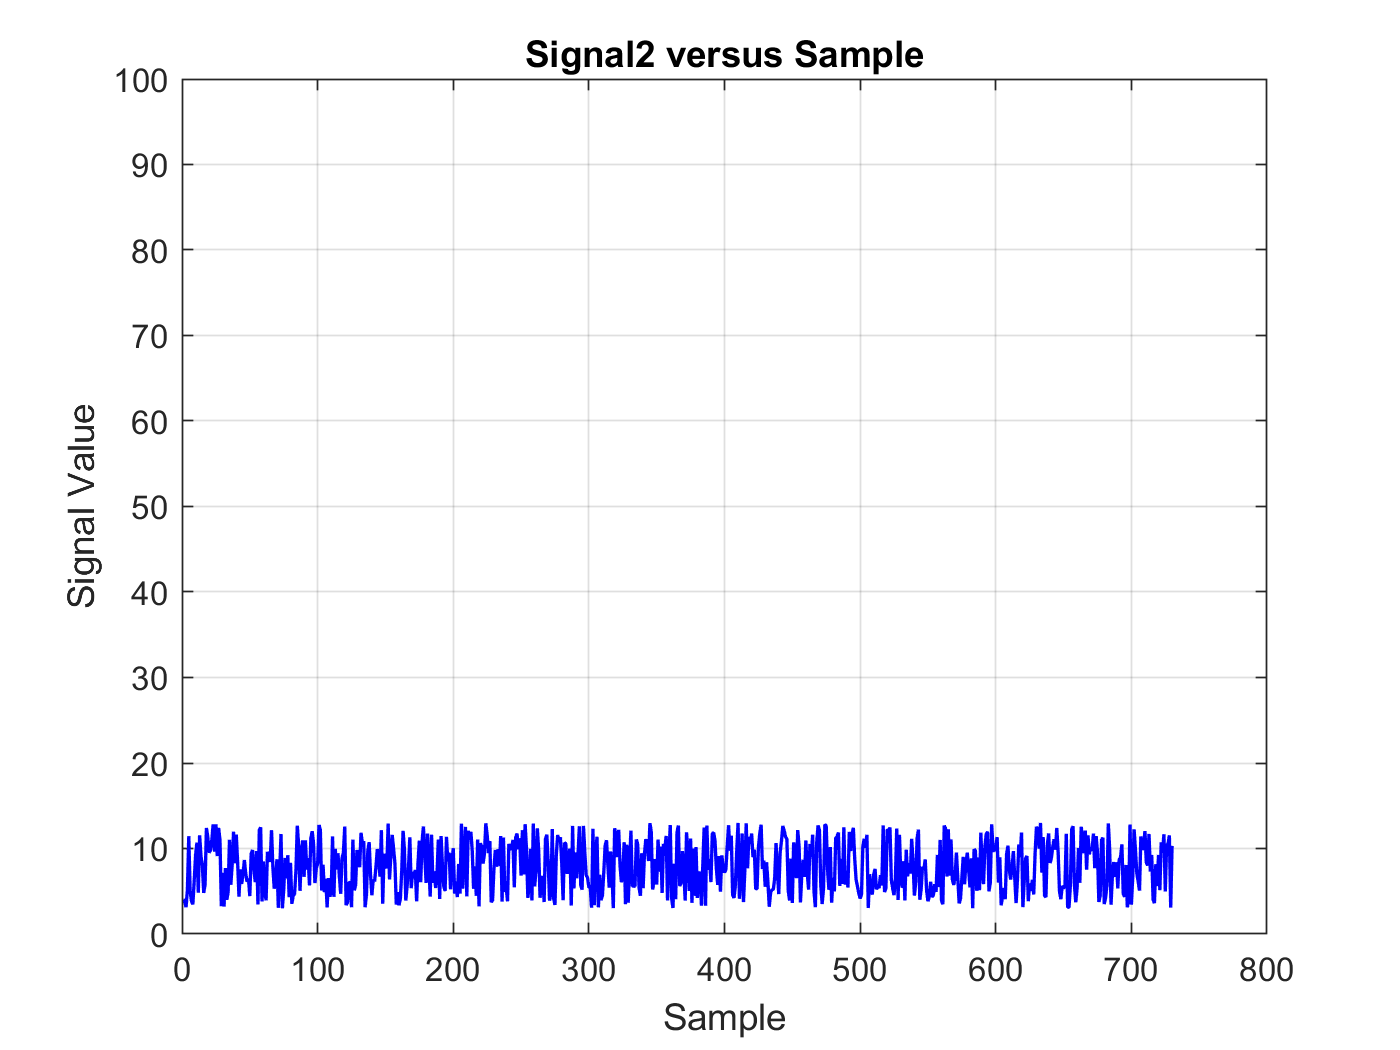


%  Signal 2
figure
plot(sample, signal_2, 'blue','LineWidth',1 )
ylim([0,100])
grid on
title('Signal2 versus Sample')
xlabel('Sample')
ylabel('Signal Value')

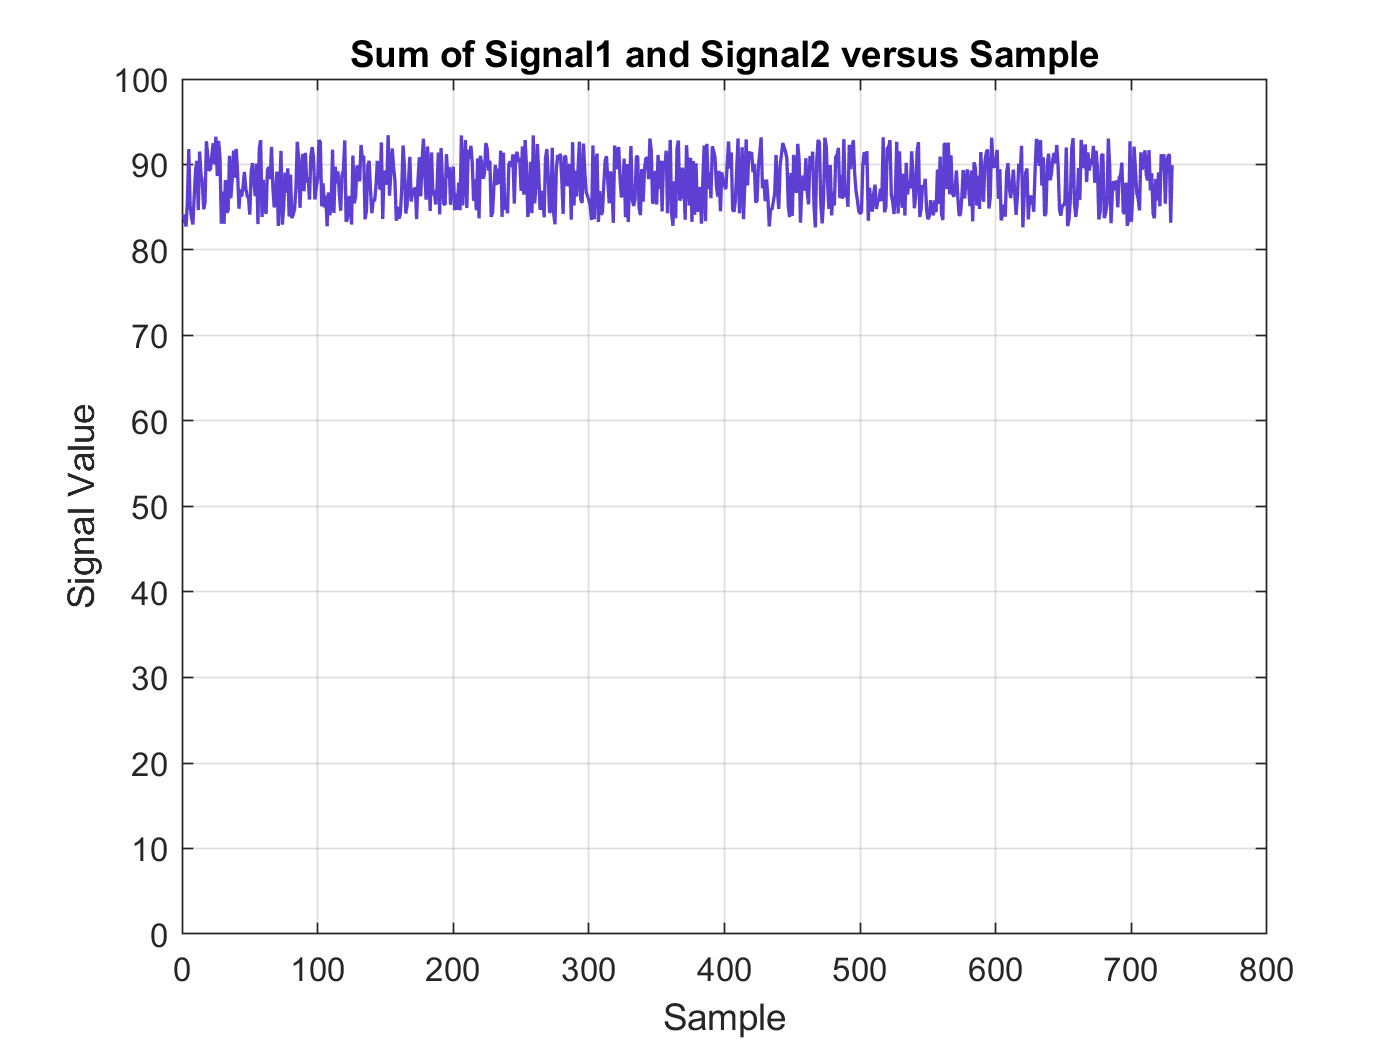


%  Sum of the two Signals
figure
plot(sample,signalSum,'Color','#5D3FD3','LineWidth',1)
grid on
title('Sum of Signal1 and Signal2 versus Sample')
ylim([0,100])
xlabel('Sample')
ylabel('Signal Value')

Press the Button below to Run the code in this section

### Step 4  Plot the Histograms

Plot histograms for each of the three variables.  Title and label the x and y axes appropriately

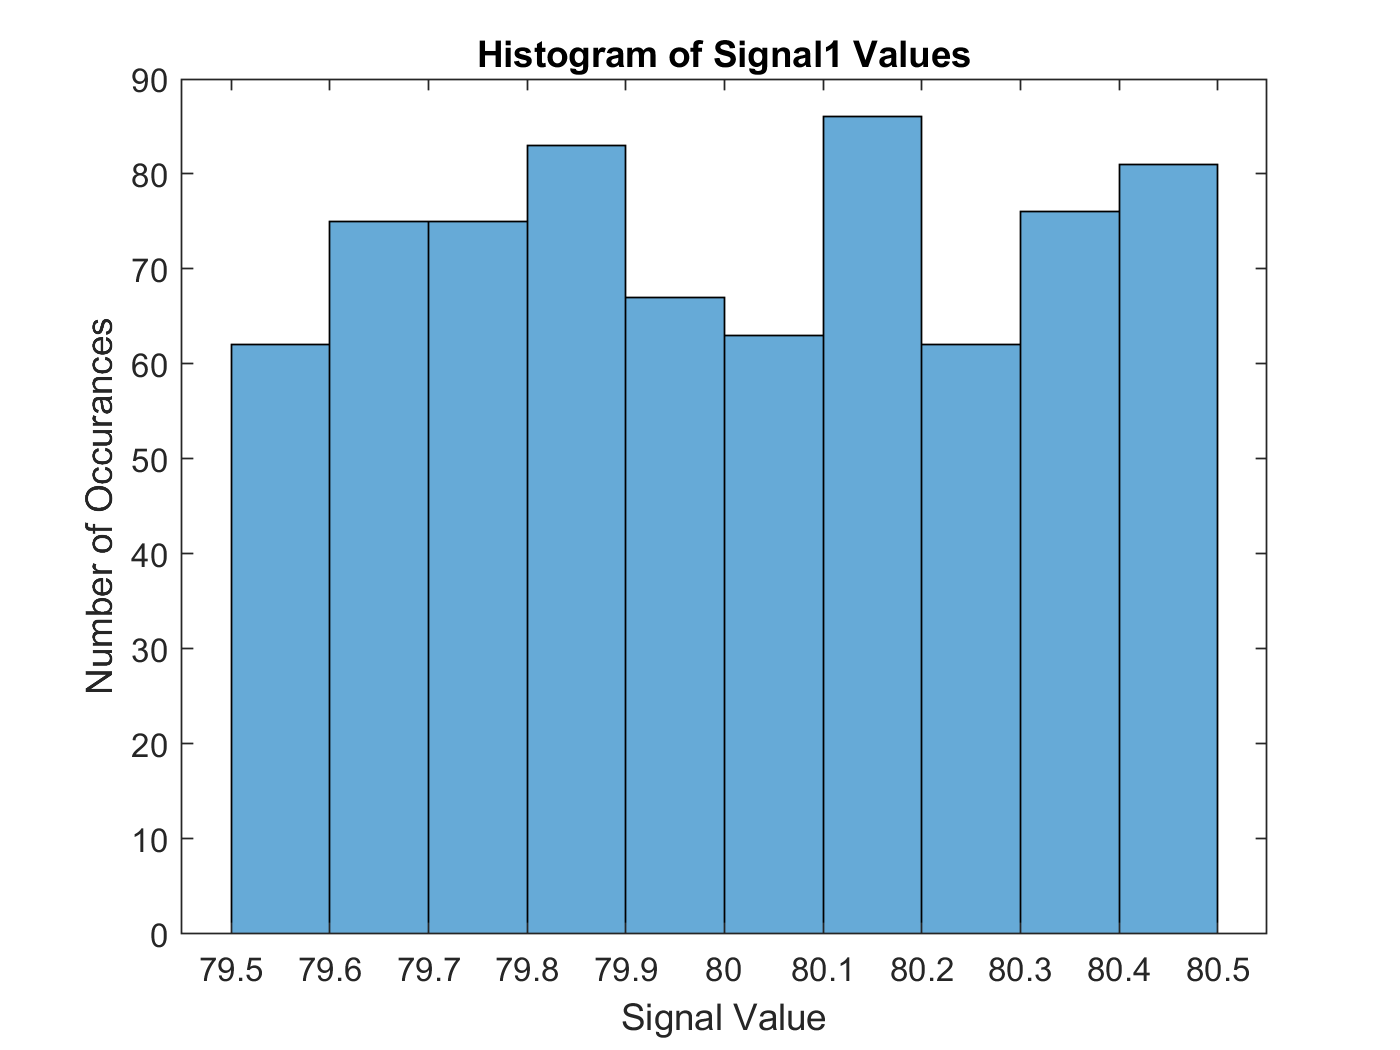

%  Plot a histogram of the signal data.


%  Solution -- Place your code here

%  Signal 1
histogram(signal_1)
title('Histogram of Signal1 Values')
xlabel('Signal Value')
ylabel('Number of Occurances')

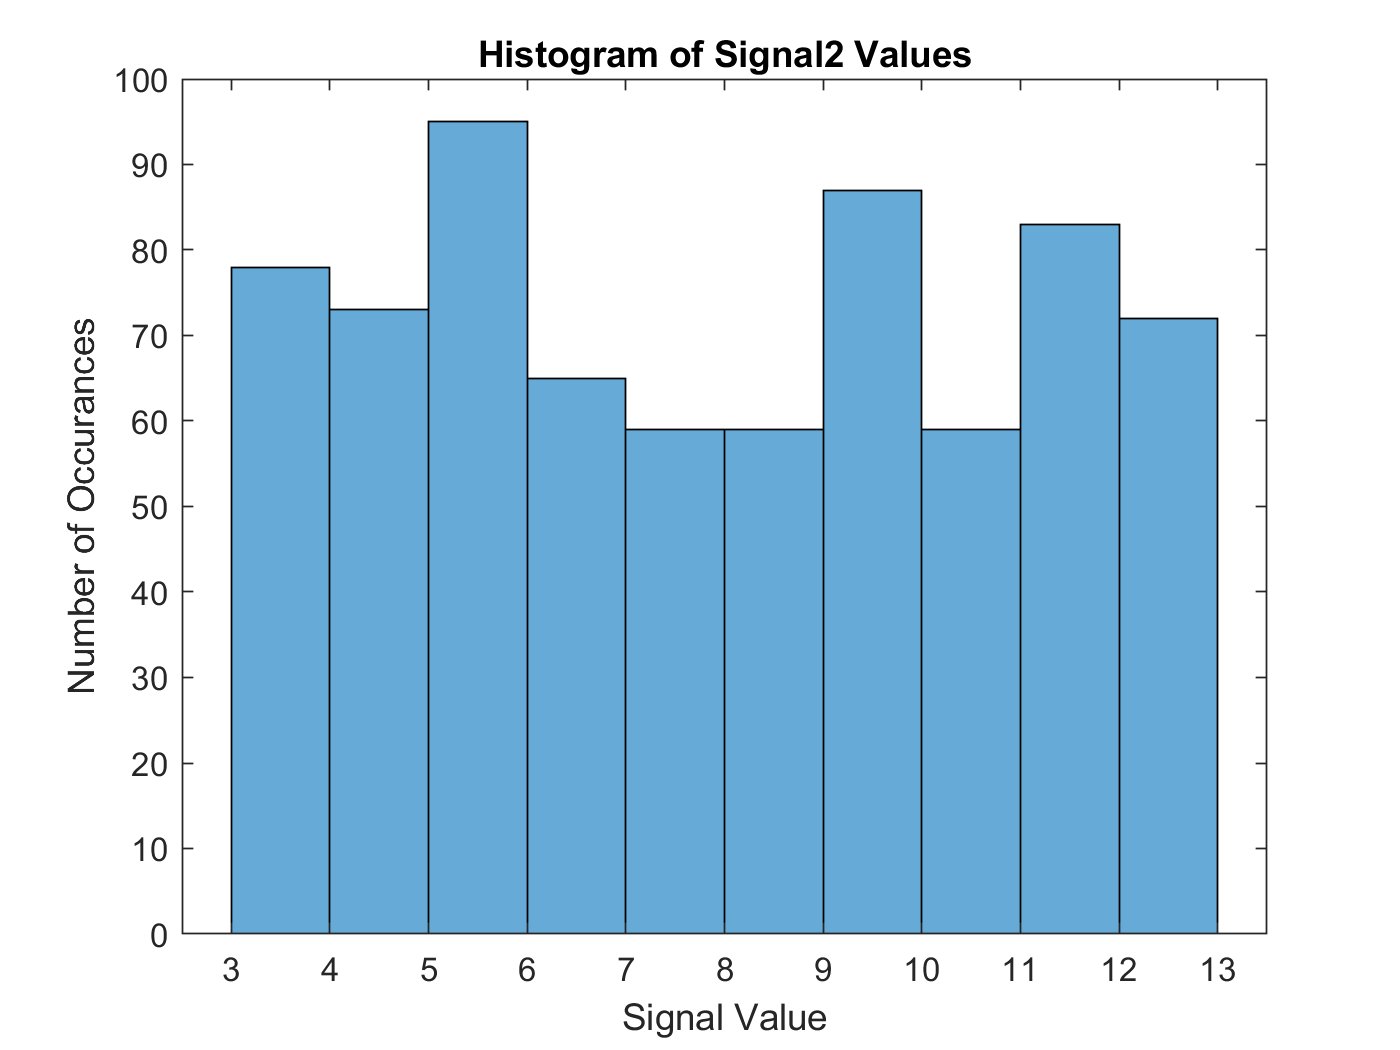


%  Signal 2
histogram(signal_2)
title('Histogram of Signal2 Values')
xlabel('Signal Value')
ylabel('Number of Occurances')

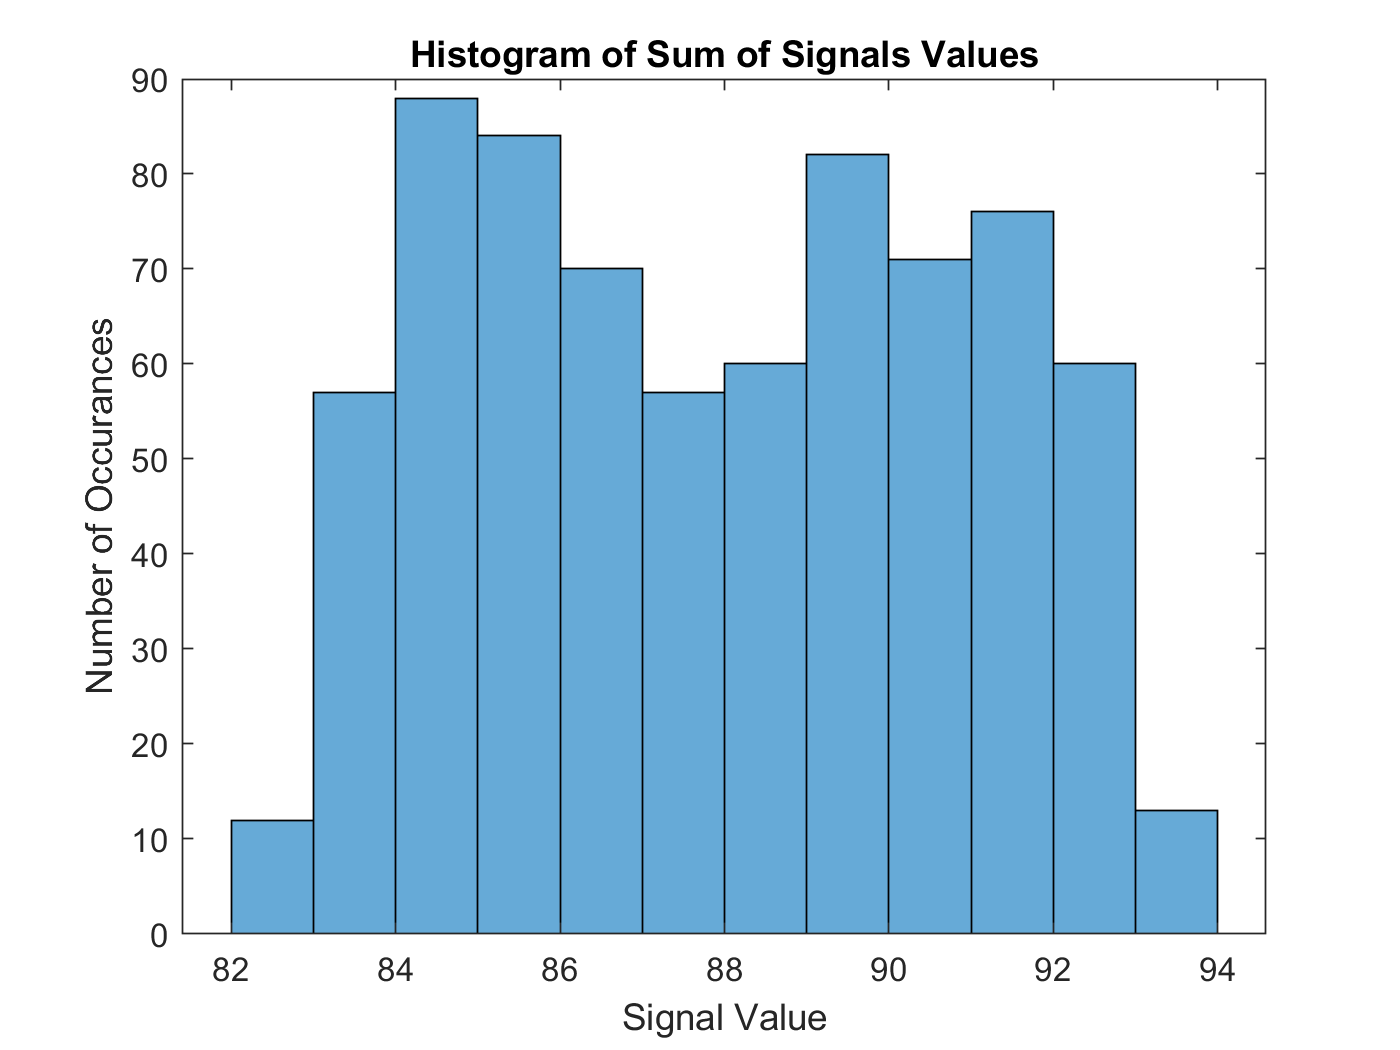


%  Sum of Signals
histogram(signalSum)
title('Histogram of Sum of Signals Values')
xlabel('Signal Value')
ylabel('Number of Occurances')

  Press the Button below to Run the code in this section

#### Question 3

Theoretically, what should the mean of the sum of the signals be equal to? Is this the case for the data given? (exactly or approximately?) (Why, or Why not?)

The calculated and measured mean of the sum of the signals are exactly equal. 

Measured

Signal 1 Mean = `80.0081`

Signal 2 Mean =` 7.9344`

Sum Signal 1 and 2 = `87.9425`

Calculated

Signal 1 Mean = 80.008 

Signal 2 Mean = 7.9344

Sum Signal 1 and 2 = 87.9425

**Numbers match up, thus, proven.**

#### Question 4

Theoretically, what should the variance of the sum of the signals be equal to? Is this the case for the data given? (exactly or approximately?) (Why, or Why not?)

    Measured  Signal_1    Signal_2    Sum

    Variance    0.5371        1.7161      1.7226

    Std Dev     0.2885         2.9450      **2.9674**

    Calculted   Signal_1    Signal_2   Sum  

    Variance    0.53713      1.7161     2.2532

    Std Dev     0.2885        2.945       **3.2335**

    Sum Variance = 0.53713 + 1.7161 = (0.2885)^2 + (2.945)^2

Theoretically, It should be equal to 2,9674, but from the measuremnts it is 3.2335.

#### Question 5

Is the standard deviation of the sum of the two signals (signal_1 + signal_2)  less than,  greater than or equal to the sum of the standard deviations of the individual components signal_1, signal_2? (exactly or approximately?) (Why, or Why not?)

**It is significantly greater. According ot the data, the sum of the individual components signal_1, signal_2 is greater than sum of the two signals (signal_1 + signal_2) by approximately %.**

#### Question 6

What probability distribution best describes the data in the histogram of the sum of the signals (uniform, triangular, normal, other)?

**Uniform**.

### Comments on Part 2

It is important to note that in all the analysis you’ve just done, the specific values for standard deviation, mean, and so forth will change as the random numbers change. In the data file, you were given a fixed set of random numbers, but in reality, each time you run such a test, the random noise changes and your answers will change slightly. You are only estimating the true mean and the true standard deviation from a finite set of data points. Thus, you will have some typical error between this value and the true mean.  The typical error is the error of the estimate of the mean.

## Part 3  Creating and Computing Statistics of Random Numbers (CLT - 15 Points)

### Step 1

In this part, you will use the MATLAB rand() function to create 12 unform random variables that range from 0 to 1 and have a mean of 0.5.  This will be done using a matrix in MATLAB.  Recall that you can create a matrix of M rows by N columns of random variables using rand(M, N).  You will then create a variable that is the sum of the first two random variable columns and an additional variable that is the sum of all 12 variables.  You will investigate the properties of those variables.

%  Create 12 uniformly distributed random variables with 2000 values for
%  each variable.  Make each variable a column with 2000 rows
%  Use the MATLAB rand( rows, columns ) function

%  Solution -- Place your code here
A = rand(2000, 12)

A =     0.2928    0.0455    0.7640    0.8919    0.9138    0.2075    0.1075    0.6560    0.3033    0.8937    0.5933    0.9482
    0.0950    0.2930    0.6366    0.8200    0.0743    0.5153    0.6804    0.9386    0.7799    0.8162    0.3409    0.3585
    0.0114    0.1321    0.5456    0.7321    0.4715    0.9989    0.8462    0.6716    0.7162    0.9474    0.7927    0.6189
    0.5926    0.0019    0.9014    0.2023    0.3605    0.6608    0.4603    0.9741    0.3283    0.2403    0.2679    0.6019
    0.0620    0.2208    0.7927    0.5598    0.3056    0.0069    0.6874    0.9766    0.7725    0.5797    0.9878    0.2219
    0.9777    0.4561    0.6568    0.2088    0.1744    0.8881    0.8670    0.5913    0.1277    0.1888    0.7883    0.6766
    0.7083    0.0286    0.0662    0.0523    0.3507    0.8331    0.5518    0.0961    0.5760    0.3513    0.3752    0.9277
    0.2897    0.8721    0.4846    0.3069    0.9436    0.5003    0.5154    0.3266    0.3558    0.6063    0.7461    0.7745
    0.5057    0.0788    0.23

   Press the Button below to Run the code in this section

### Step 2

Plot the histogram of the uniform random numbers in the first column.  Add an appropriate title and axes labels

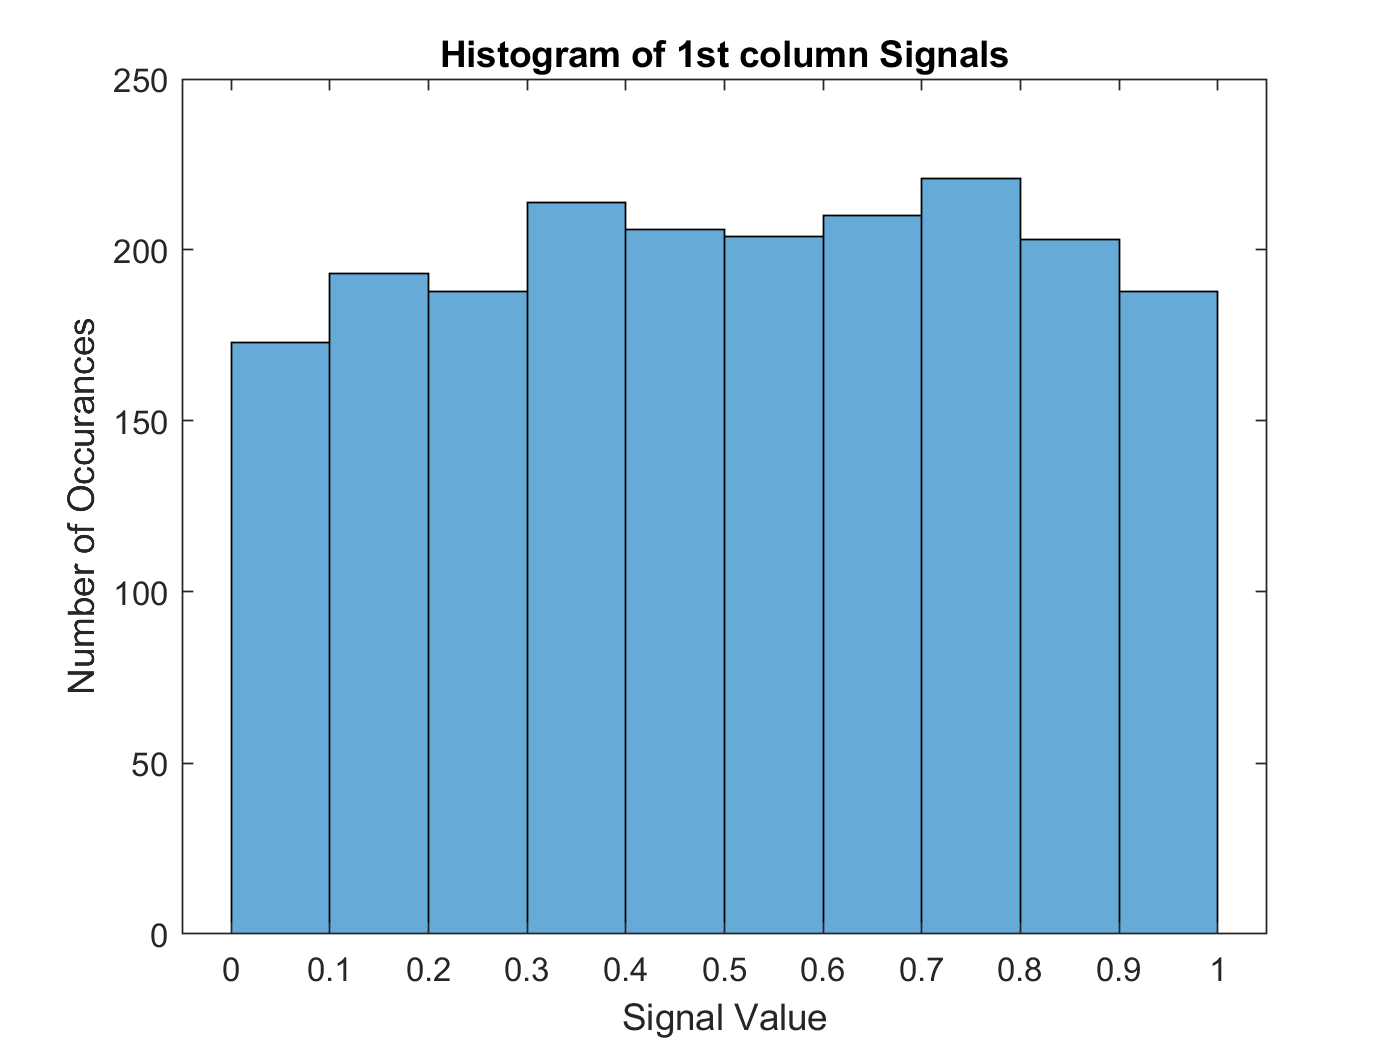

%  The histogram of the first random variable

%  Solution -- Place your code here


histogram(A(:,1))
title('Histogram of 1st column Signals')
xlabel('Signal Value')
ylabel('Number of Occurances')

   Press the Button below to Run the code in this section

### Step 3

Create a variable that is the sum of the first two columns.  Recall that you can select a single column from a matrix using the : operator.  That  is  x = M( :, 2) selects all the values in the second column of the matrix M 

%  Create a variable that is the sum of the first two columns.  

%  Solution -- Place your code here
B = A(:,1) + A(:,2); % Sum of column 1 and 2

   Press the Button below to Run the code in this section

### Step 4

Plot the histogram of the sum of the two random variables. Add an appropriate title and axes labels.

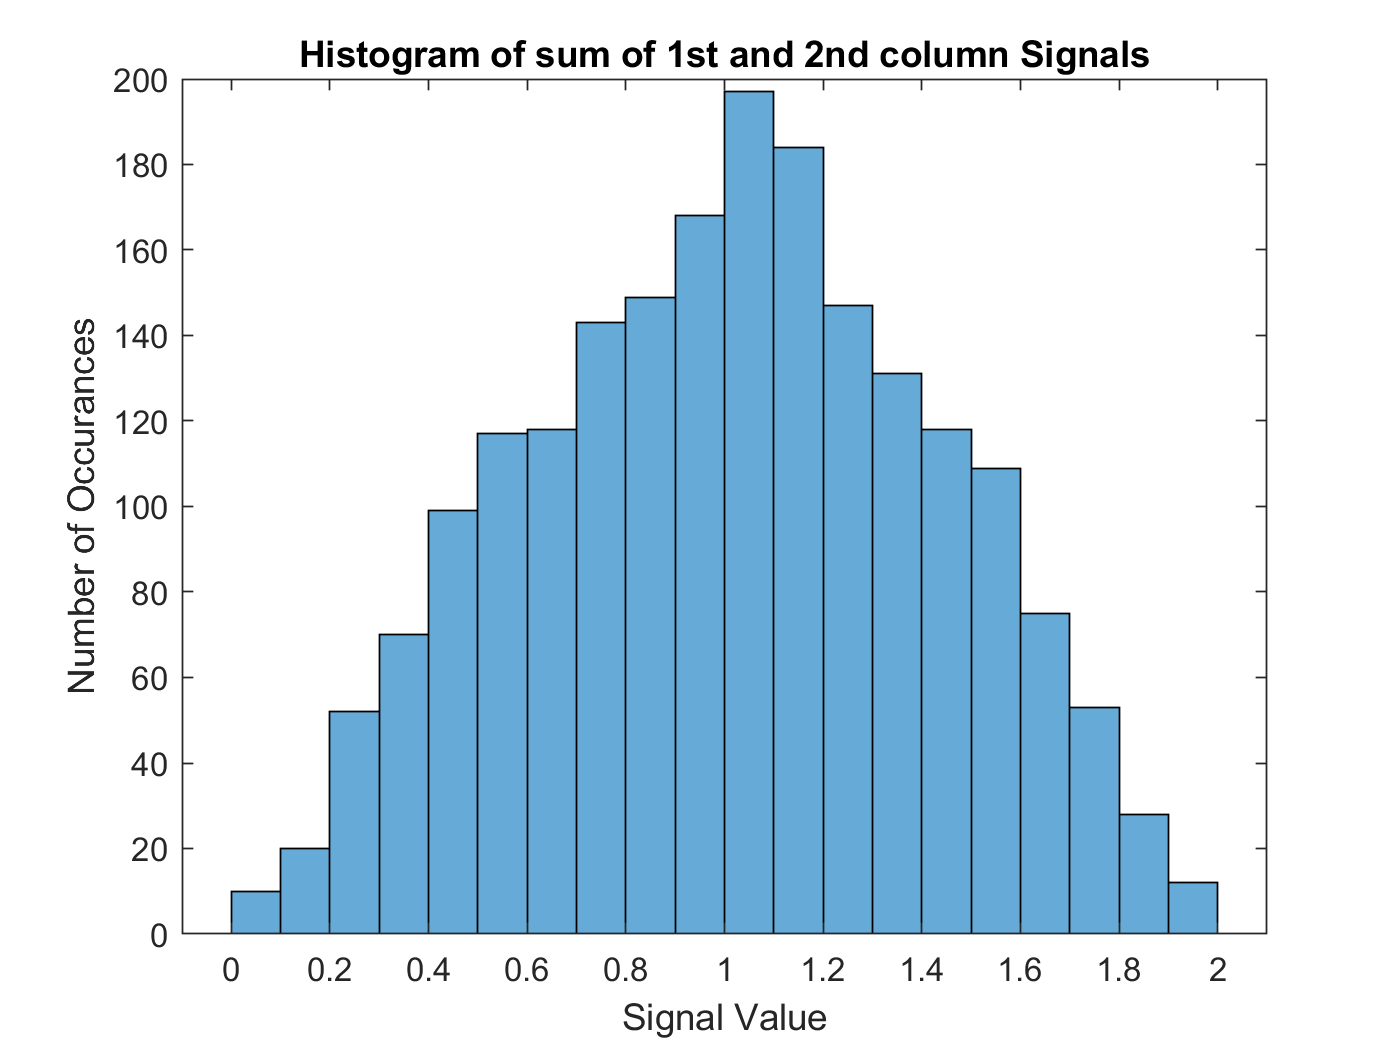

%  The histogram of the first sum of two uniform random variables

%  Solution -- Place your code here

histogram(B)
title('Histogram of sum of 1st and 2nd column Signals')
xlabel('Signal Value')
ylabel('Number of Occurances')

   Press the Button below to Run the code in this section

### Step 5

Create a variable that is the sum of all 12 random variables in the matrix, that is the sum of all the values in each row.  The MATLAB sum function will sum all the values of a matrix across a selected DIMENSON.  The result of the sum should be a matrix with 1 column of length 2000, in other words 1 column by 2000 rows.

%  Create a variable that is the sum of all 12 random variables
%
%  Example sumRows = sum( M, 2)

%  Solution -- Place your code here
S = sum(A,2)

S =     6.6176
    6.3488
    7.4846
    5.5924
    6.1737
    6.6015
    4.9172
    6.7217
    4.8002
    6.9420


   Press the Button below to Run the code in this section

### Step 6

Plot the histogram of the sum of the 12 random variables. Add an appropriate title and axes labels.

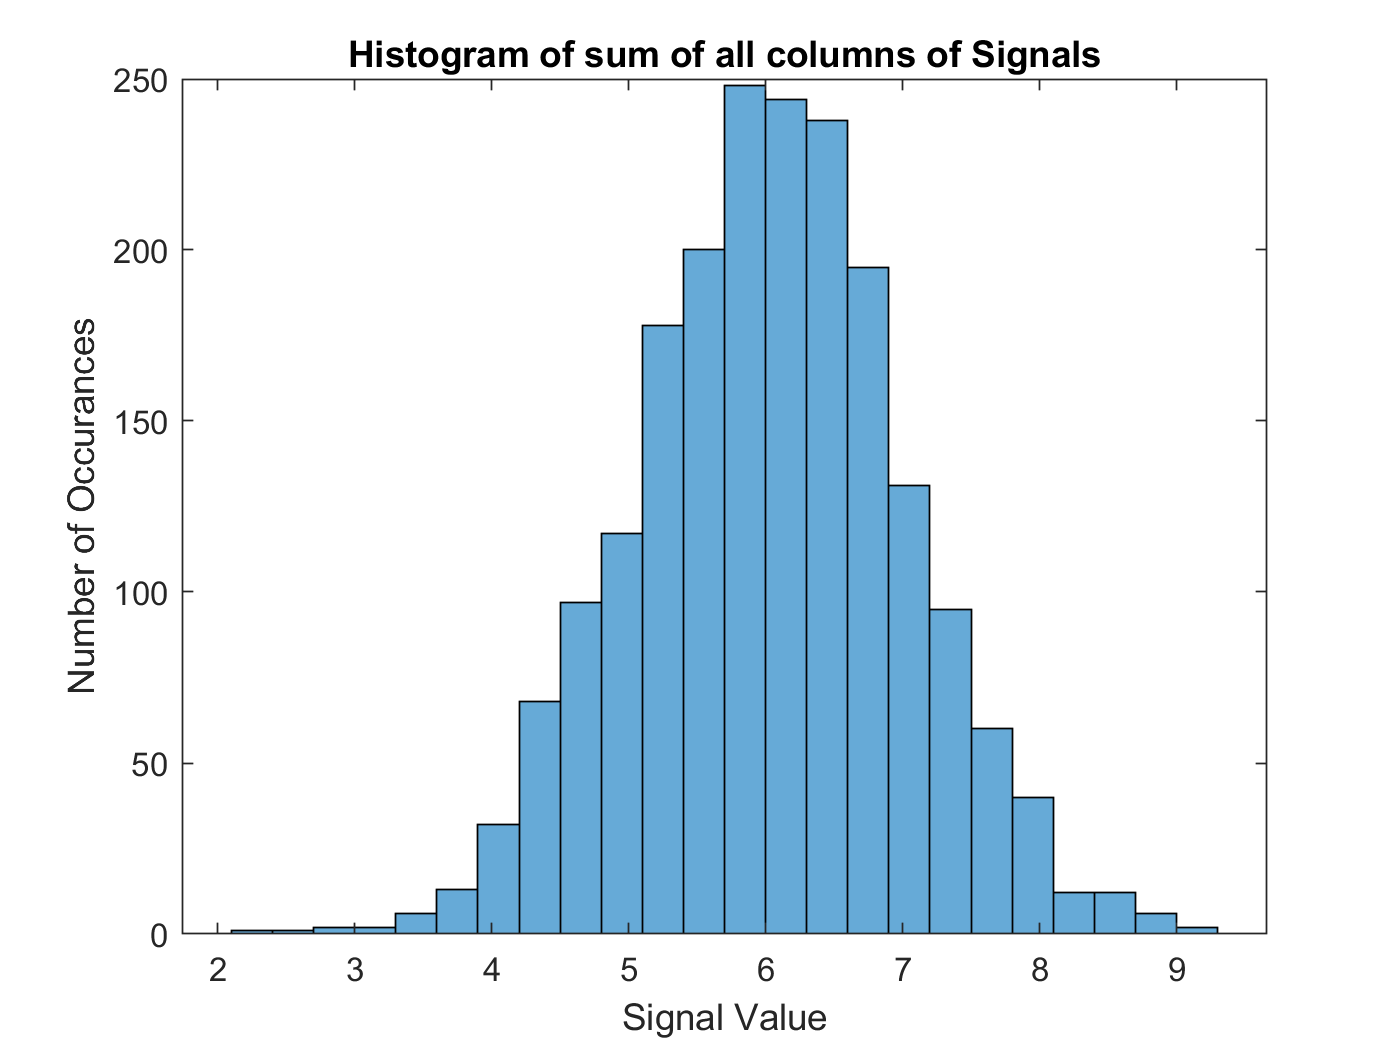

%  The histogram of the sum of 12 uniform random variables

%  Solution -- Place your code here

histogram(S)
title('Histogram of sum of all columns of Signals')
xlabel('Signal Value')
ylabel('Number of Occurances')

   Press the Button below to Run the code in this section

#### Question 7

Carefully compare the distributions (from the histogram) of a single uniform random variable, the sum of two uniform random variables and the sum of 12 uniform random variables.  How are each of these distributions best described (uniform, triangular, normal, other)? How does this compare to theory? What theory applies to the sum of the 12 random signals?

#### Type your answer here:

## Part 4 Estimating Temperature Cycles (15 Points)

### Step 1

Load the matlab datafile from myCourses "Rochester_Average_Temp.mat".  This is data for the average daily temperature in Rochester in degress Fahrenheit over a two year period.  This will load four variables into the workspace: 'sample' and 'msrdTemp', 'estTemp', 'error'

%  Clear the workspace and load the data file
clear
load Rochester_Average_Temp.mat
[sample, msrdTemp, estTemp, error]

ans =     1.0000   35.2000   26.3103    8.8897
    2.0000   38.9000   26.1920   12.7080
    3.0000   52.2000   26.0803   26.1197
    4.0000   40.1000   25.9751   14.1249
    5.0000   28.9000   25.8765    3.0235
    6.0000   23.1000   25.7845   -2.6845
    7.0000   14.3000   25.6991  -11.3991
    8.0000   17.3000   25.6204   -8.3204
    9.0000    3.8000   25.5484  -21.7484
   10.0000   -2.3000   25.4831  -27.7831


   Press the Button below to Run the code in this section

### Step 2

Plot the values of the measured temperature 'msrdTemp' over a two year period.  Add appropriate title and axes labels.

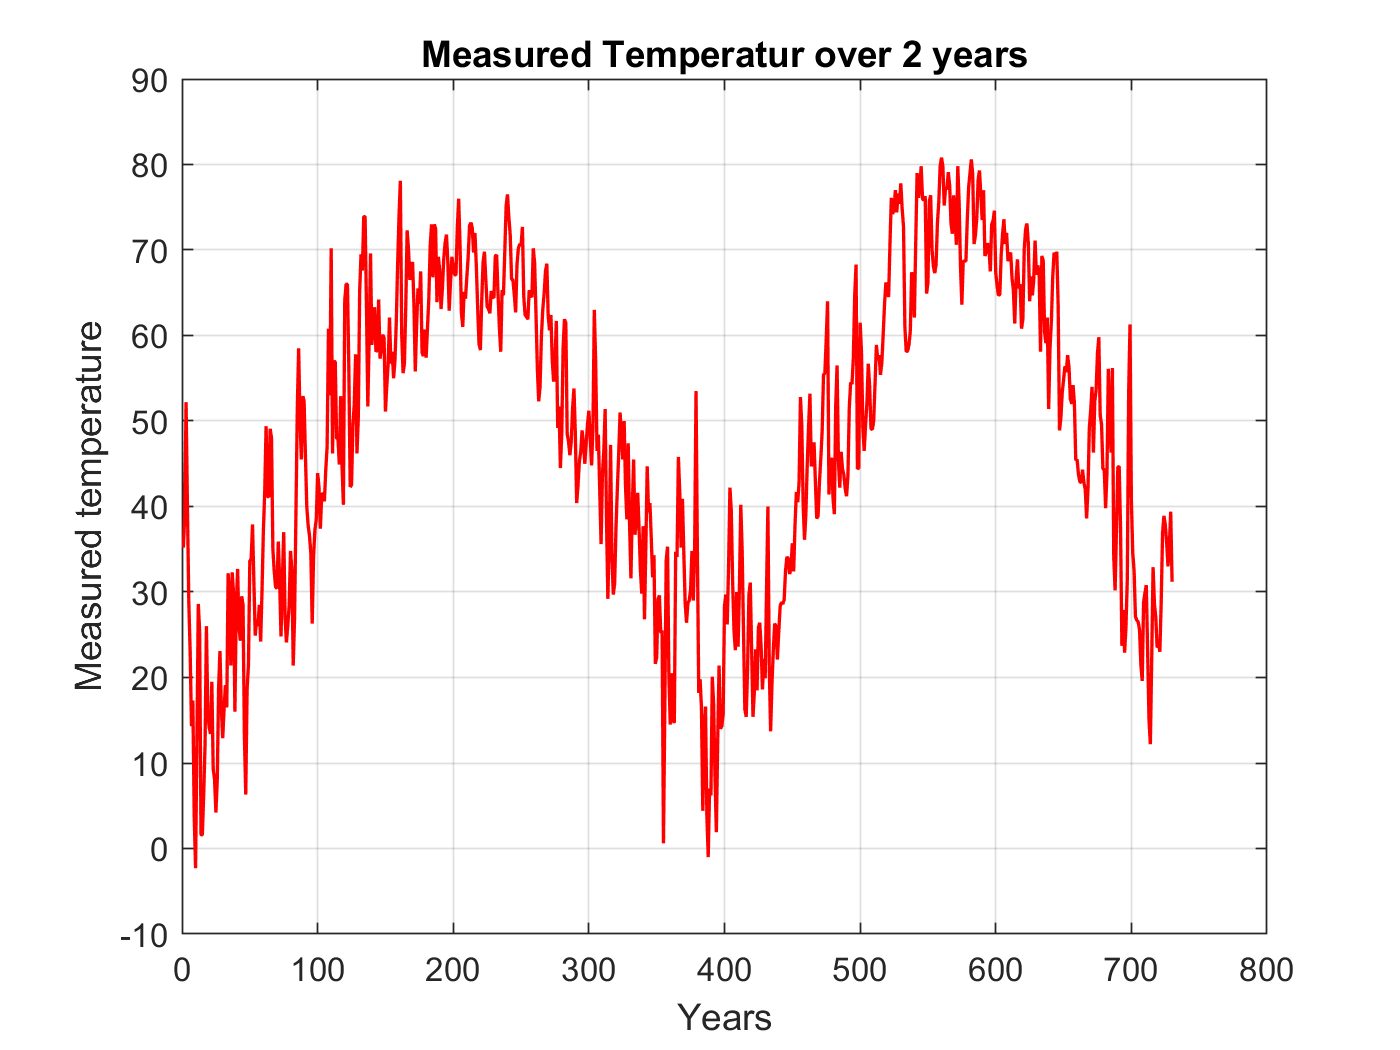

%  Plot of the average temperature in Rochester over a two year period.
%  Add a grid

%  Solution -- Place your code here
figure
plot(sample,msrdTemp,'Color','Red','LineWidth',1)
grid on
title('Measured Temperatur over 2 years')
xlabel('Years')
ylabel('Measured temperature')

  Press the Button below to Run the code in this section

### Step 3

The daily average temperature can be estimated by a constant value of 48.2 F plus a sinusoidal variation of amplitude 23 degrees F and phase of -1.9 radians. Putting this all together, the estimated temperature is: 

Daily average temperature (F)  = 48.2+23*SIN((2*PI()*day/365)-1.9) 

The estimated daily temperature value is  already computed in the variable 'estTemp'. The error between the actual measured data and the estimated data is in the variable 'error'.

Plot the error of the estimate.  Add title and axes labels.

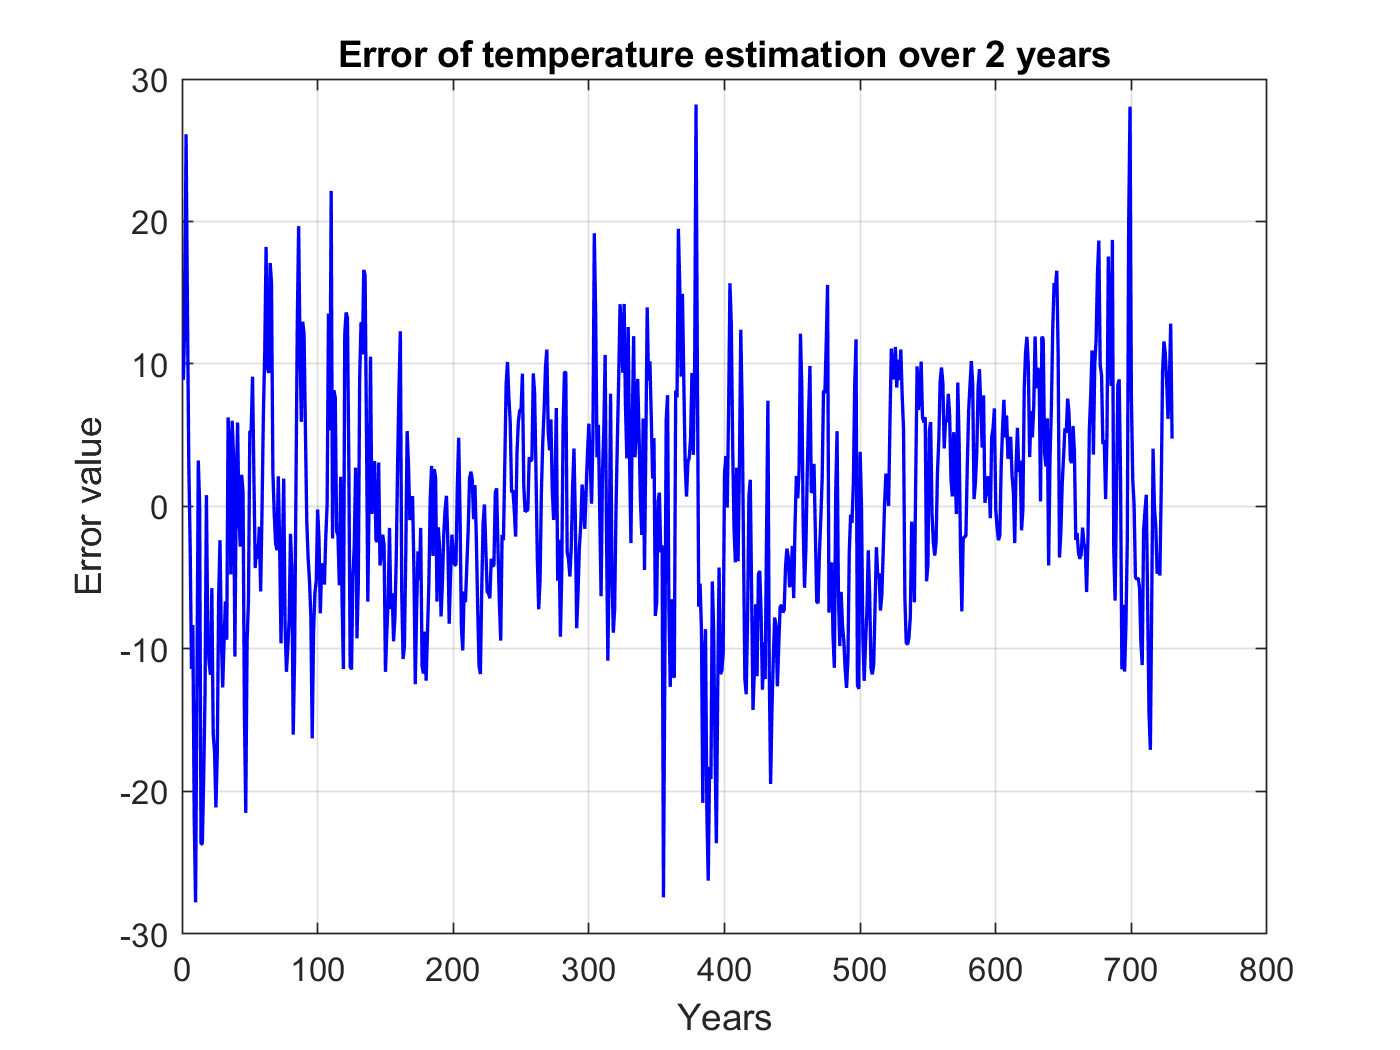

%  Plot of the error of the measured and average temperature in Rochester over a two year period.
%  Add a grid

%  Solution -- Place your code here
figure
plot(sample,error,'Color','Blue','LineWidth',1)
grid on
title('Error of temperature estimation over 2 years')
xlabel('Years')
ylabel('Error value')

  Press the Button below to Run the code in this section

### Step 4

Plot the histogram of the error in temperature.  Add titles and label the axes.

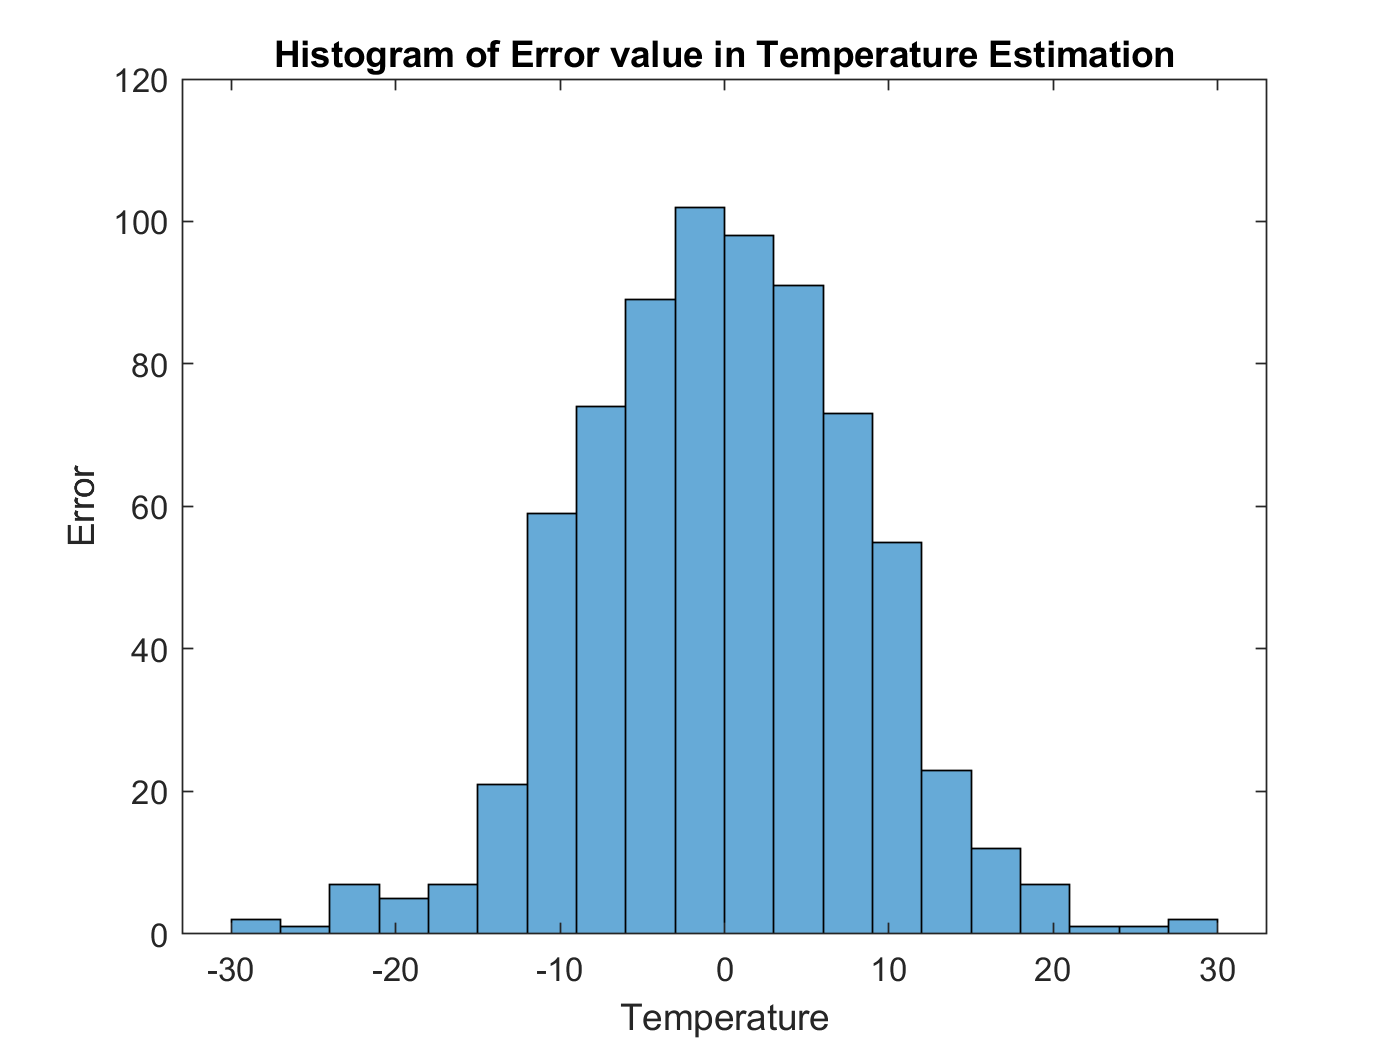

%  The histogram of the temperature error

%  Solution -- Place your code here
histogram(error)
title('Histogram of Error value in Temperature Estimation')
xlabel('Temperature')
ylabel('Error')

   Press the Button below to Run the code in this section

### Step 5

Compute the standard deviation of the temperature error

%  The standard deviation of the error temperatures

%  Solution -- Place your code here

StDevErr = std(error)

StDevErr = 8.3260

   Press the Button below to Run the code in this section

#### Question 8

How would you describe the distribution of the error of the estimate (normal, uniform, triangular, other)? Explain.

#### Type your answer here:

Normal, Bell-shaped. According to the graph.

### Step 6

If the estimator predicts that the temperature today will be 55 degrees F, what is the signal to noise ratio of this estimate, given the standard deviation of the error value you just calculated?   What is the value of the signal considered to be?

%  Signal to noise ratio calculation

%  Solution -- Place your code here
SNR = 55^2/StDevErr^2

SNR = 43.6371

   Press the Button below to Run the code in this section

## Part 5  Quantization Noise -- Uncorrelated Signal (15 Points)

### Step 1

Load the matlab datafile from myCourses "Quantized_Signal_1.mat".  This is data for a continuous sinusoidal signal and one that is quantized with a quantization size of 1.  Four variables are loaded into the MATLAB workspace

sample -- the sample number

conSignal -- The high resolution continuous sinusoidal signal

qSignal -- The quantized sinusoidal signal

error -- The error between the continuous signal and the quantized signal

The formula for the sinewave is: = 127.5 + 127.5*sin( sample / 10 )

Note: The sinewave is **not** tightly correlated with the sampling frequency. 

Plots of the signals are made for you below

%  Clear the workspace and load the data file
clear
load Quantized_Signal_1.mat
[sample, conSignal, qSignal, error]

ans =          0  127.5000  128.0000   -0.5000
    1.0000  140.2288  140.0000    0.2288
    2.0000  152.8303  153.0000   -0.1697
    3.0000  165.1788  165.0000    0.1788
    4.0000  177.1508  177.0000    0.1508
    5.0000  188.6268  189.0000   -0.3732
    6.0000  199.4919  199.0000    0.4919
    7.0000  209.6378  210.0000   -0.3622
    8.0000  218.9629  219.0000   -0.0371
    9.0000  227.3742  227.0000    0.3742


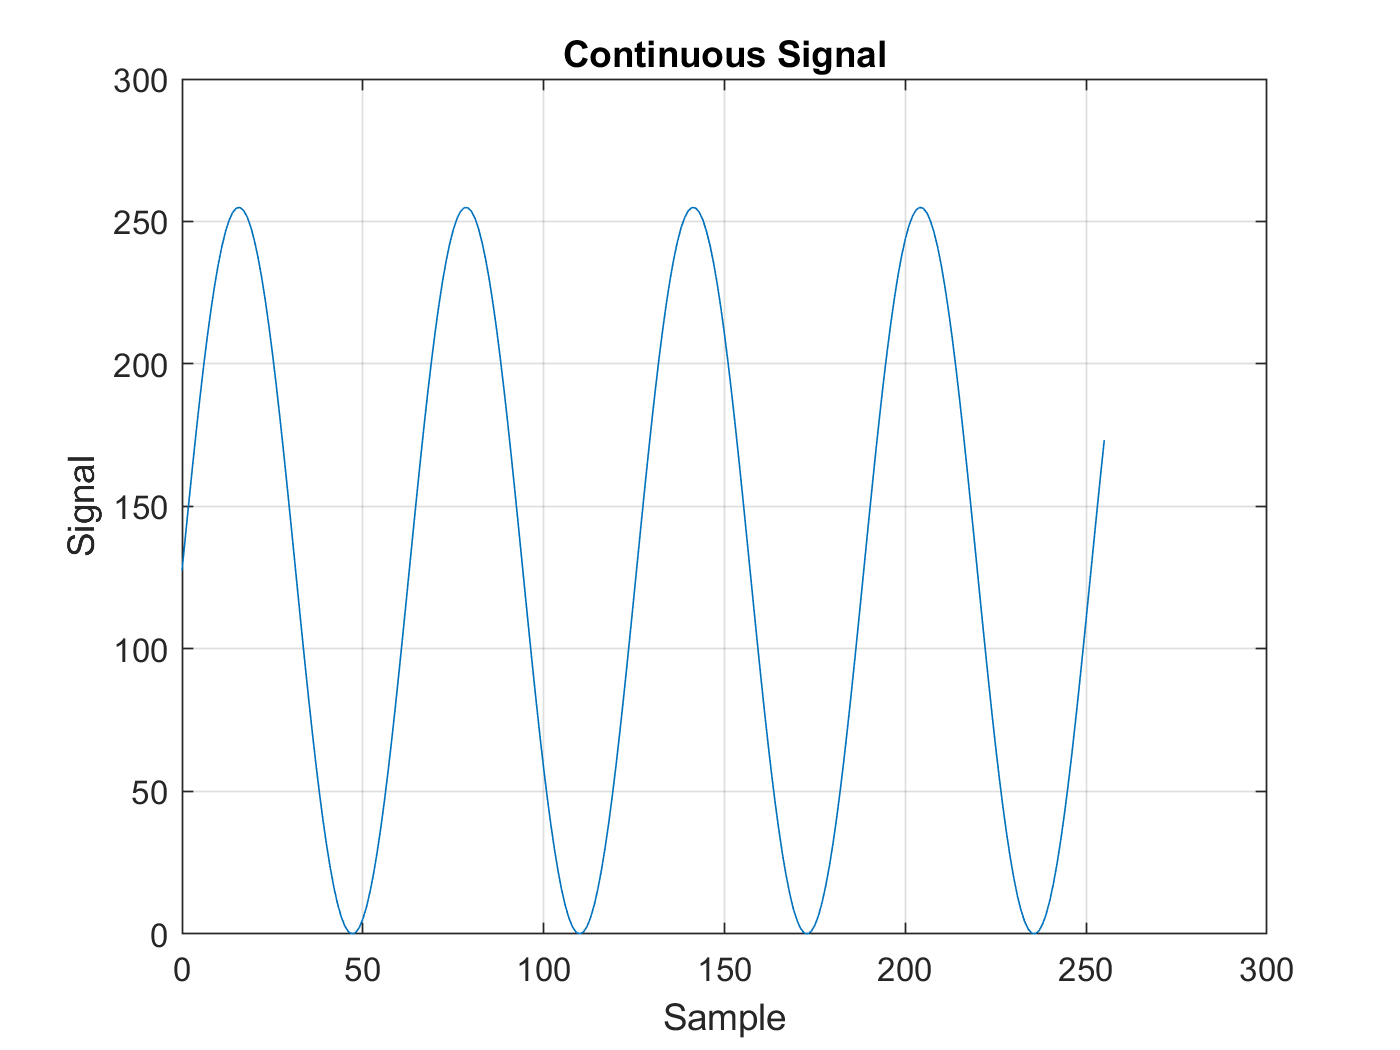


%  Plot the signals

figure
plot(sample, conSignal)
grid on
title('Continuous Signal')
xlabel('Sample')
ylabel('Signal')

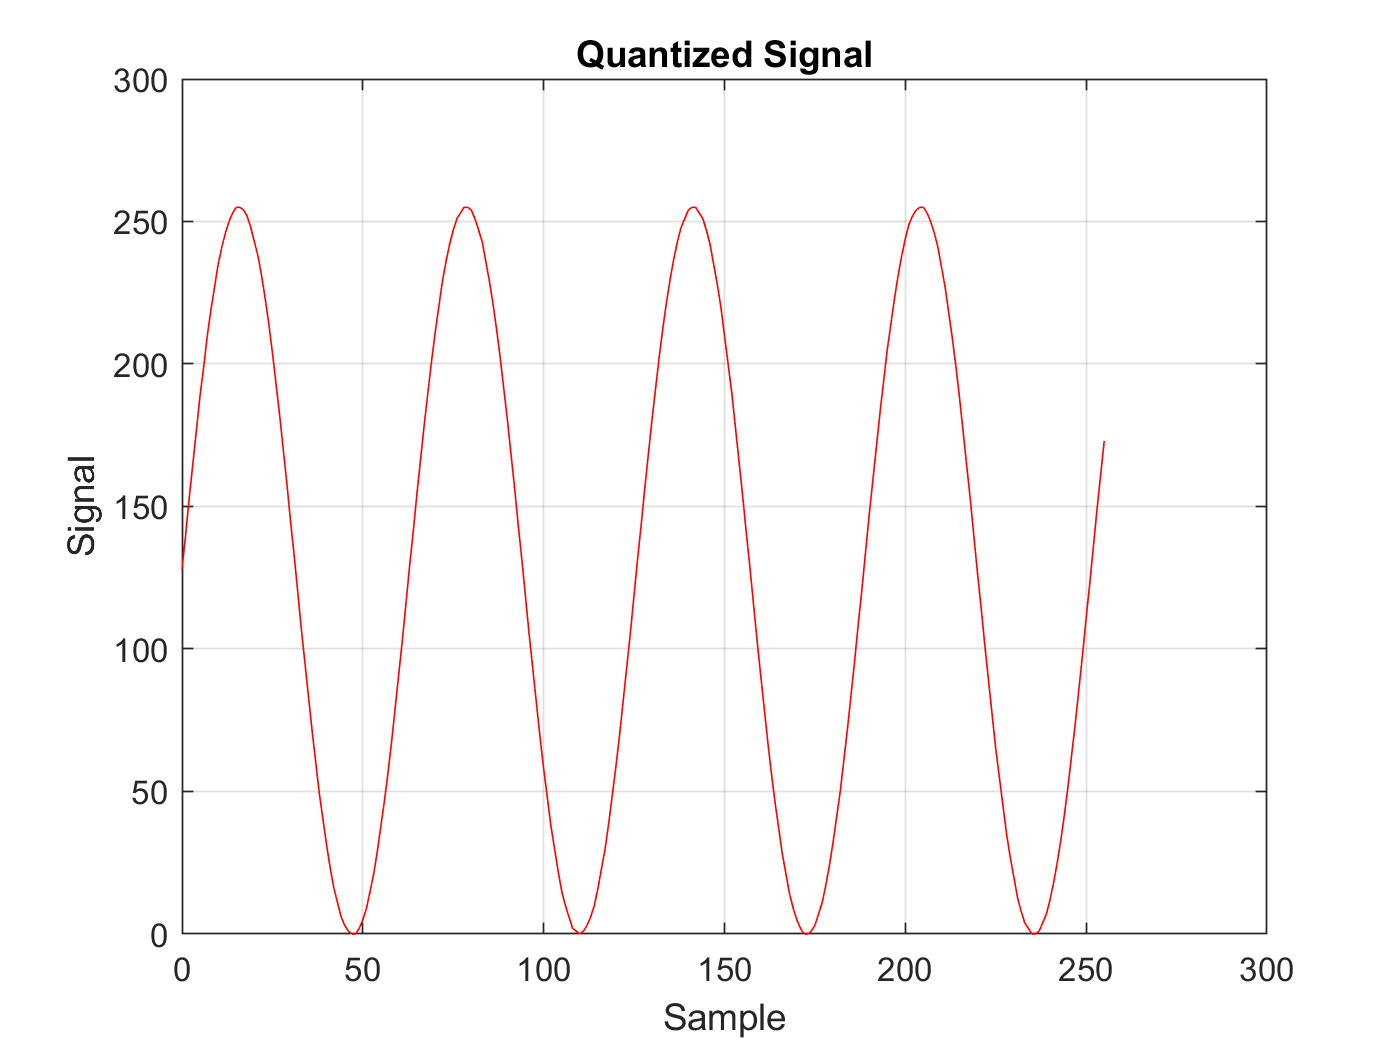


figure
plot(sample, qSignal,'r')
grid on
title('Quantized Signal')
xlabel('Sample')
ylabel('Signal')

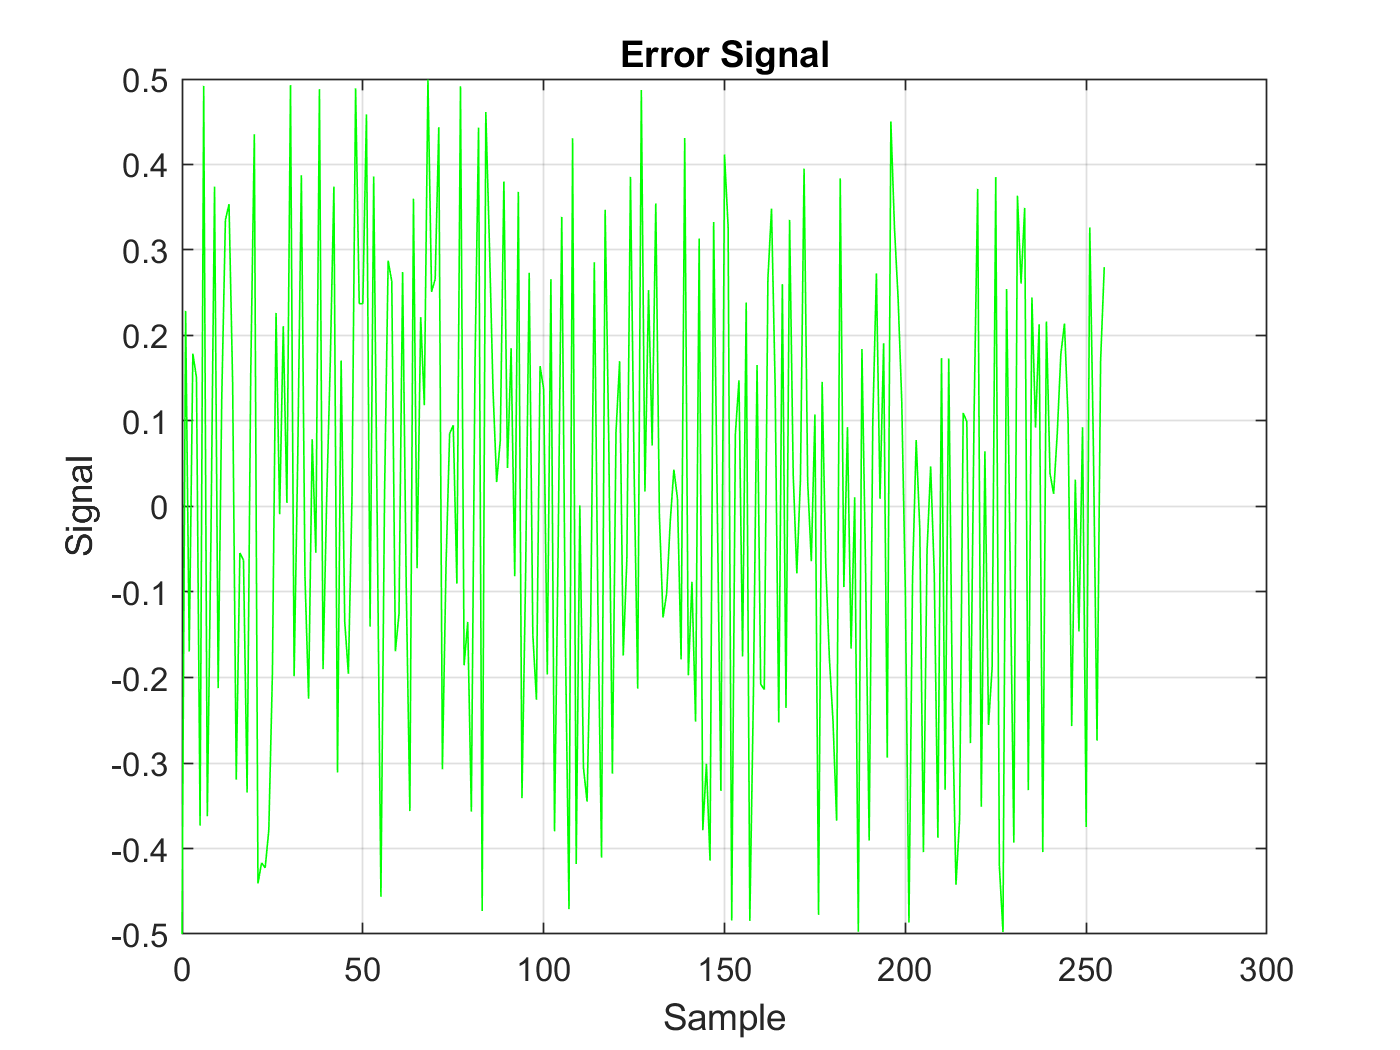


figure
plot(sample, error,'g')
grid on
title('Error Signal')
xlabel('Sample')
ylabel('Signal')

   Press the Button below to Run the code in this section

### Step 2

First - Plot a histogram of the quantization error using the histogram bins edges given in the variable 'binEdges' in the code section below.  The option to add bin edges is:

histogram( x, binEdges )

Then, create a historgram showing the cumulative values by adding the PropertyName 'Normalization' with a value of 'cdf'.  This represents the cumulative density function of the data.

example:

histogram(x, binEdges, 'Normalization','cdf')

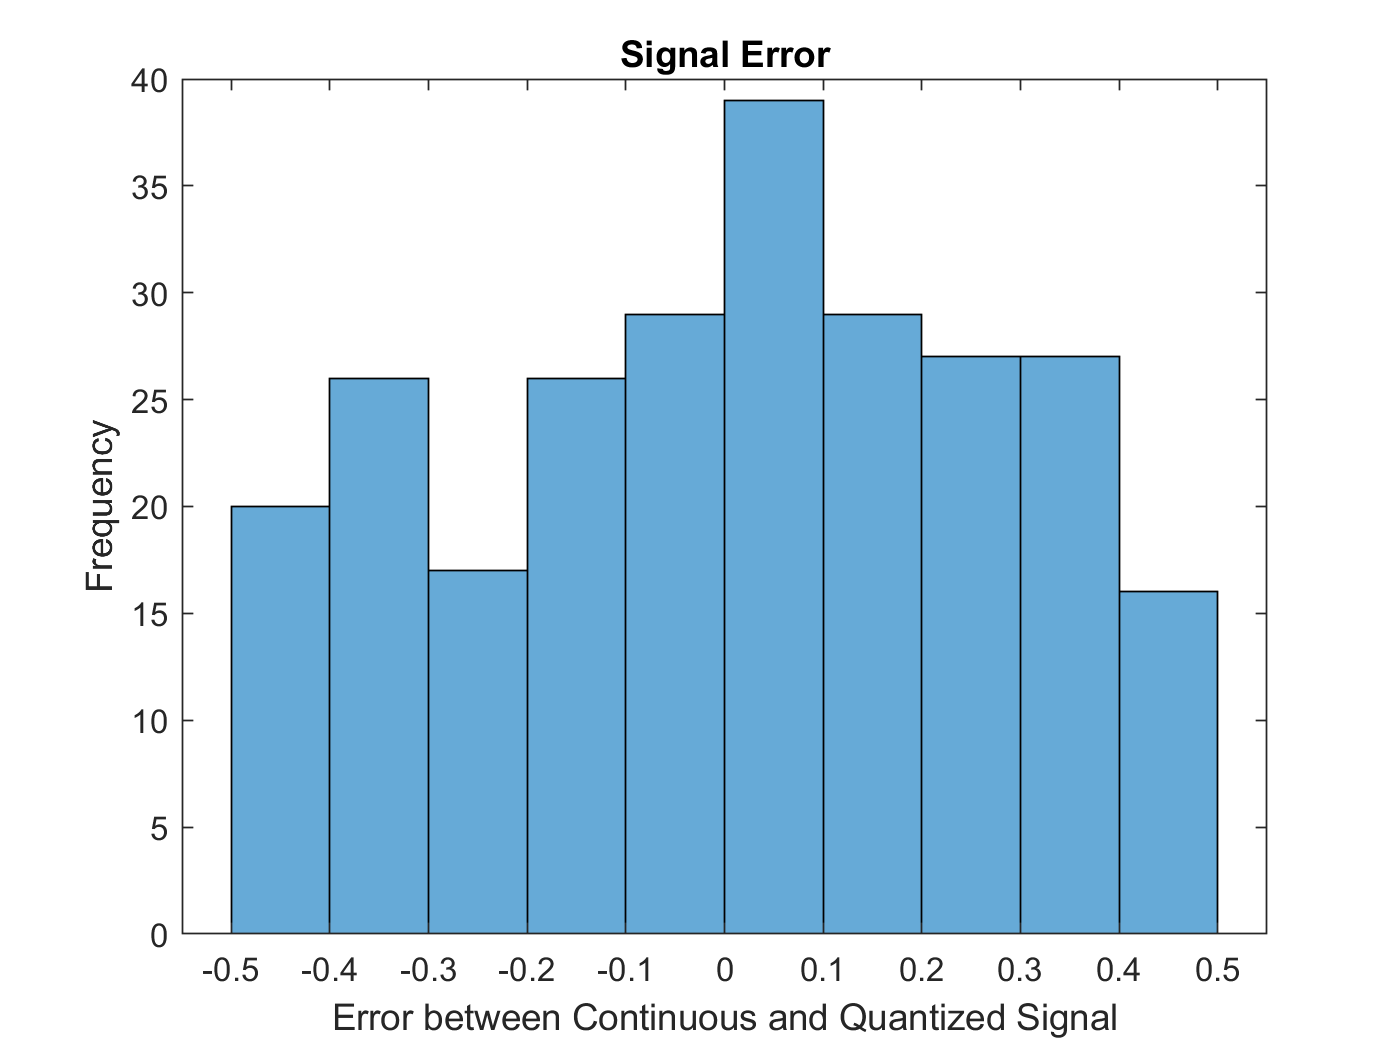

%  Plot the histogram of the quantization error

binEdges = -0.5:0.1:0.5;

%  Solution -- place your code here
histogram(error, binEdges)
title('Signal Error')
xlabel('Error between Continuous and Quantized Signal')
ylabel('Frequency')

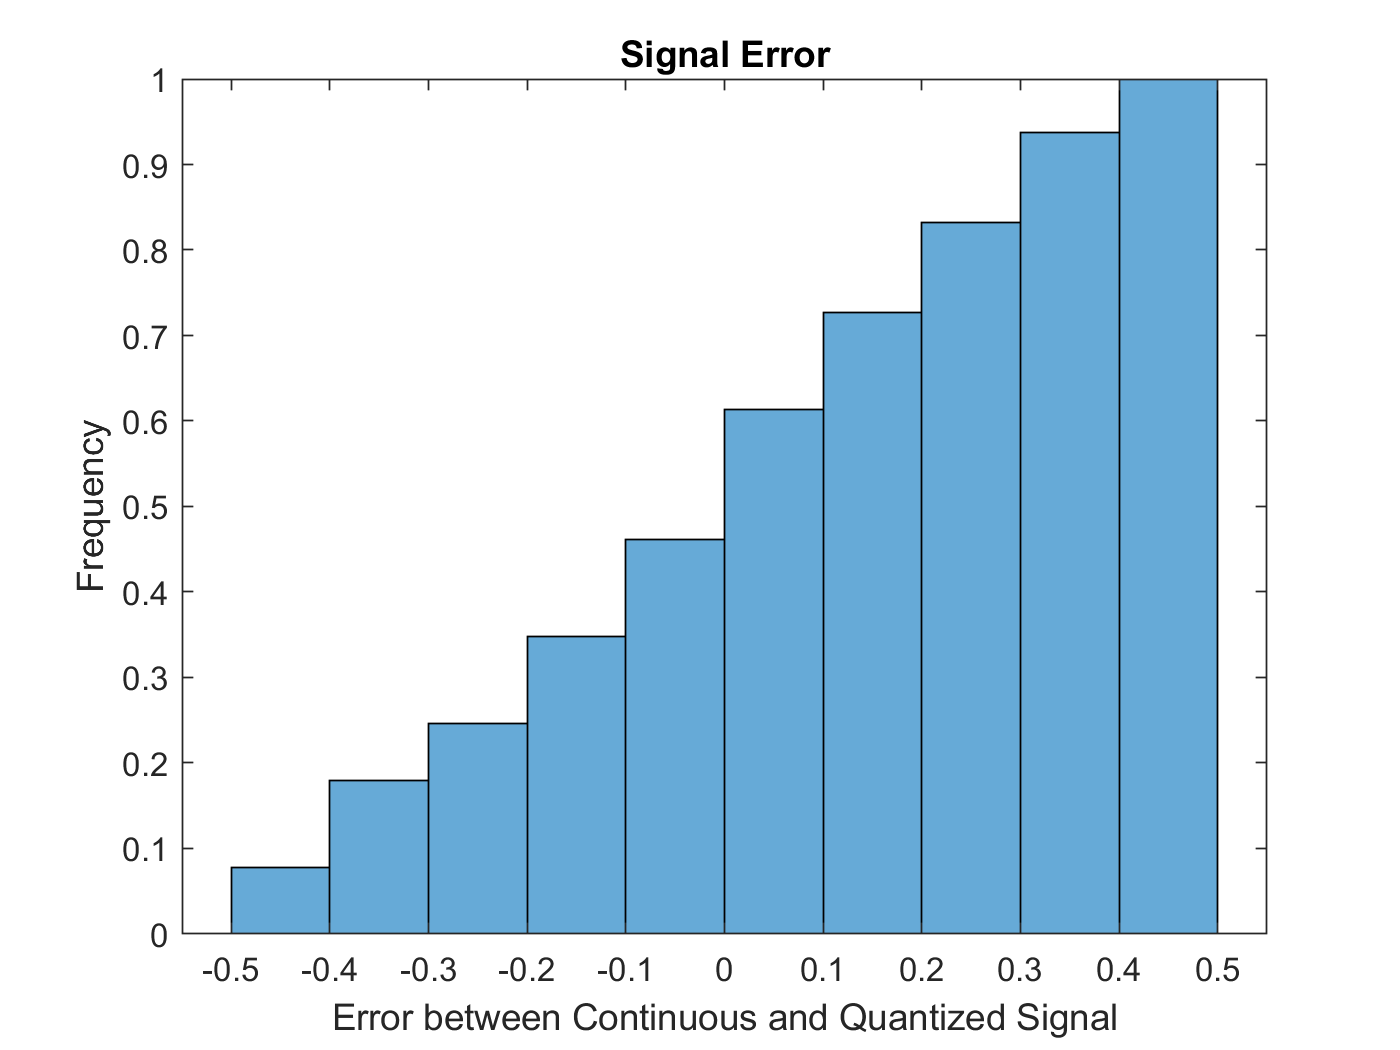

histogram(error, binEdges,'Normalization','cdf')
title('Signal Error')
xlabel('Error between Continuous and Quantized Signal')
ylabel('Frequency')

   Press the Button below to Run the code in this section

#### Question 9

How would you describe the distribution of the error of the estimate (normal, uniform, triangular, other)?  What do you observe about the cumulative density function and how does it relate to the histogram of the data?

#### Type your answer here: 

The distribution of the error of the estimate is somewhat uniform.

The cumulative density function has somewhat similiar sized steps becuase of somehwat distribution.

## Part 6  Quantization Noise -- Correlated Signal (15 Points)

### Step 1

Load the matlab datafile from myCourses "Quantized_Signal_2.mat".  This is data for a continuous sinusoidal signal and one that is quantized with a quantization size of 1.  Four variables are loaded into the MATLAB workspace.

sample -- the sample number

conSignal -- The high resolution continuous sinusoidal signal

qSignal -- The quantized sinusoidal signal

error -- The error between the continuous signal and the quantized signal

The formula for the sinewave is: = 127.5 + 127.5*sin( 2*pi*sample / 64 )

Note: The sinewave **is** tightly correlated with the sampling frequency. 

Plots of the signals are made for you below:

%  Clear the workspace and load the data file
clear
load Quantized_Signal_2.mat
[sample, conSignal, qSignal, error]

ans =          0  127.5000  128.0000   -0.5000
    1.0000  139.9972  140.0000   -0.0028
    2.0000  152.3740  152.0000    0.3740
    3.0000  164.5113  165.0000   -0.4887
    4.0000  176.2921  176.0000    0.2921
    5.0000  187.6031  188.0000   -0.3969
    6.0000  198.3352  198.0000    0.3352
    7.0000  208.3851  208.0000    0.3851
    8.0000  217.6561  218.0000   -0.3439
    9.0000  226.0588  226.0000    0.0588


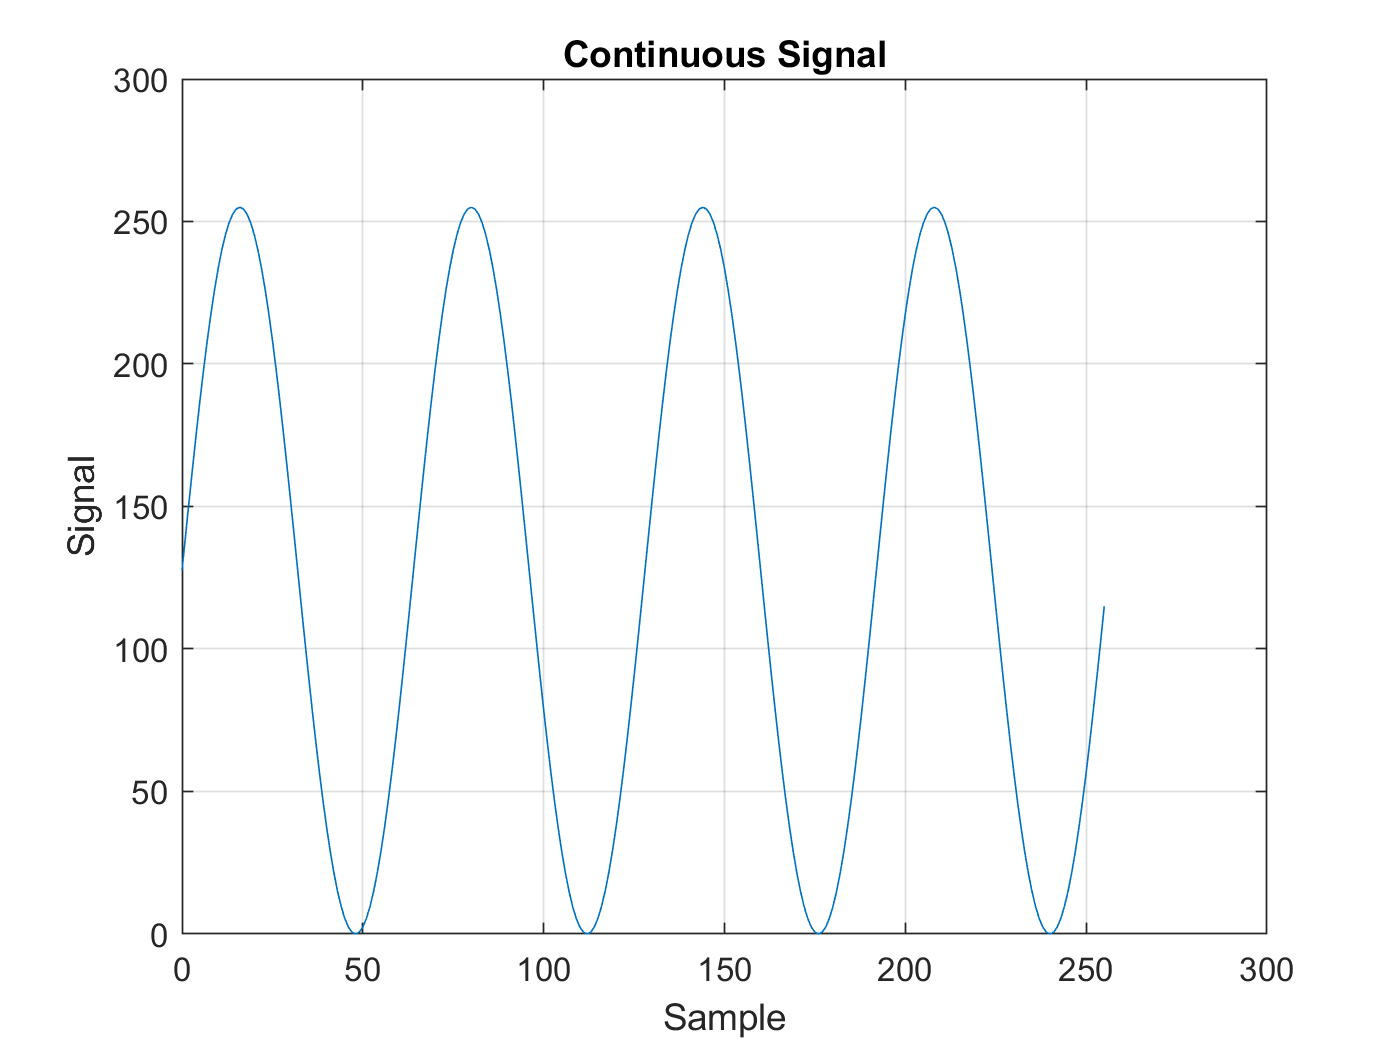


%  Plot the signals

figure
plot(sample, conSignal)
grid on
title('Continuous Signal')
xlabel('Sample')
ylabel('Signal')

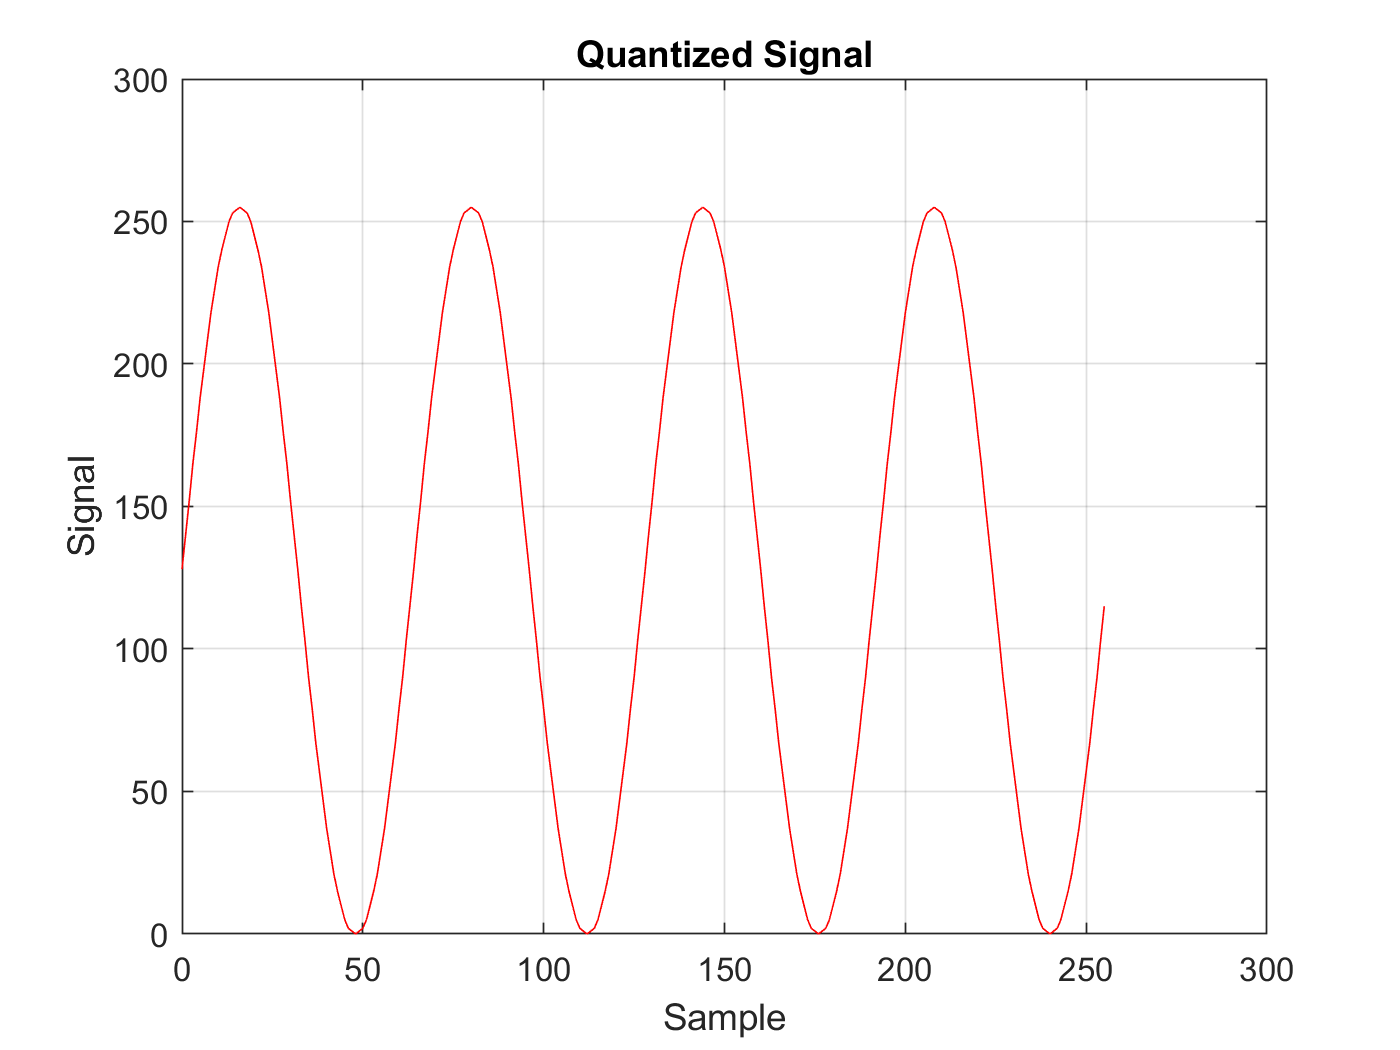


figure
plot(sample, qSignal,'r')
grid on
title('Quantized Signal')
xlabel('Sample')
ylabel('Signal')

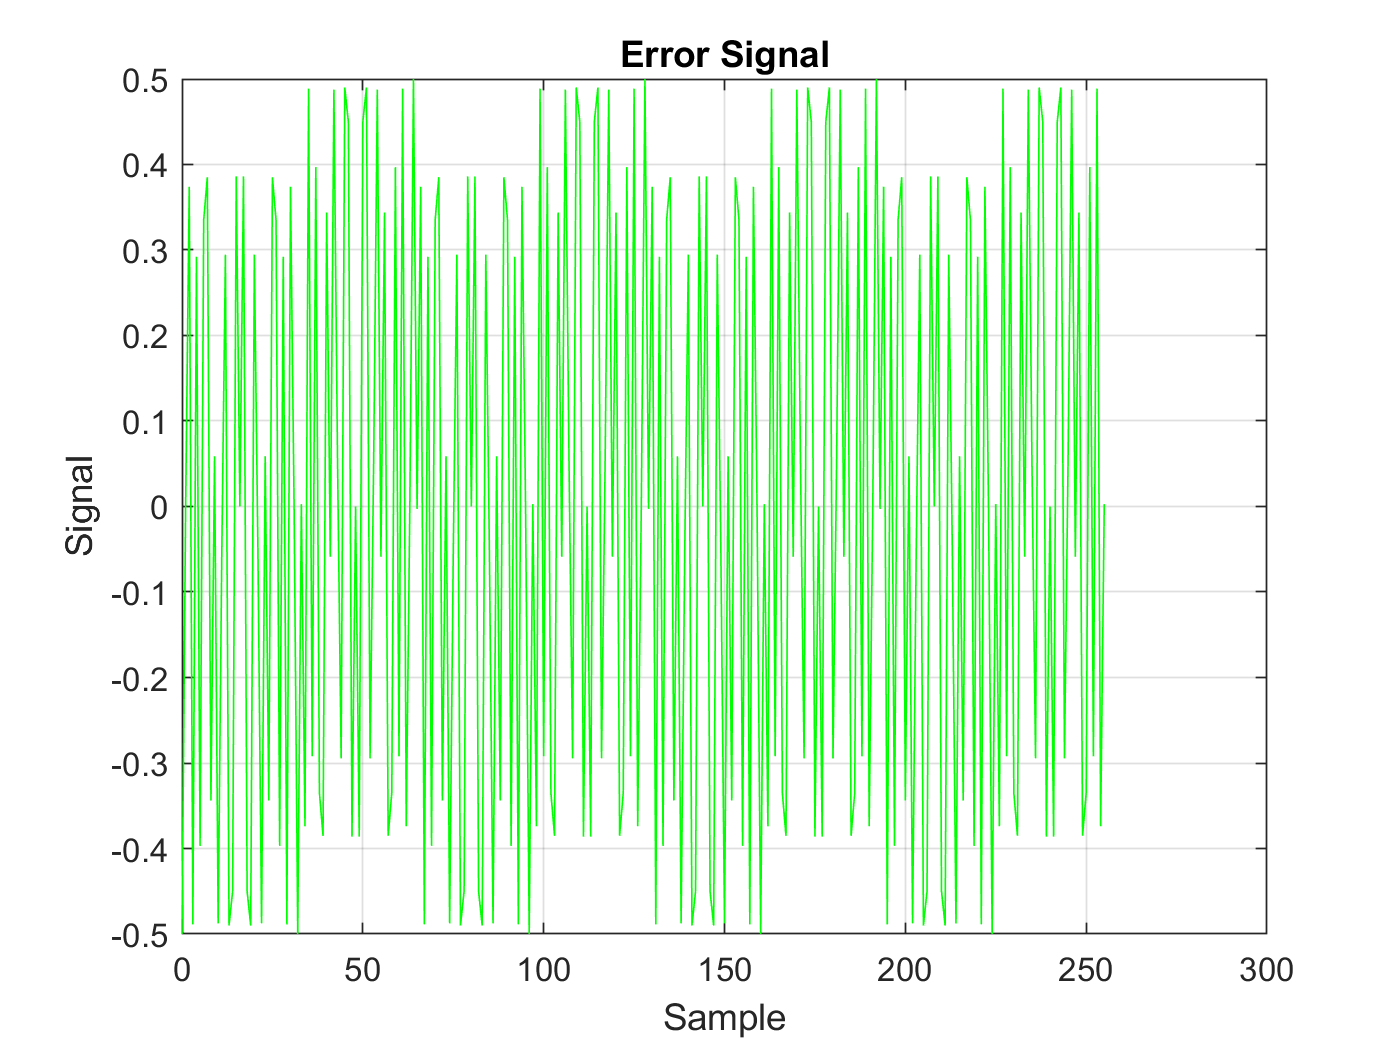


figure
plot(sample, error,'g')
grid on
title('Error Signal')
xlabel('Sample')
ylabel('Signal')

   Press the Button below to Run the code in this section

### Step 2

First - Plot a histogram of the quantization error using the histogram bins edges given in the variable 'binEdges' in the code section below.  The option to add bin edges is:

histogram( x, binEdges )

Then, create a  historgram showing the cumulative values by adding the PropertyName 'Normalization' with a value of 'cdf'.  This represents the cumulative density function of the data.

example:

histogram(x, binEdges, 'Normalization','cdf')

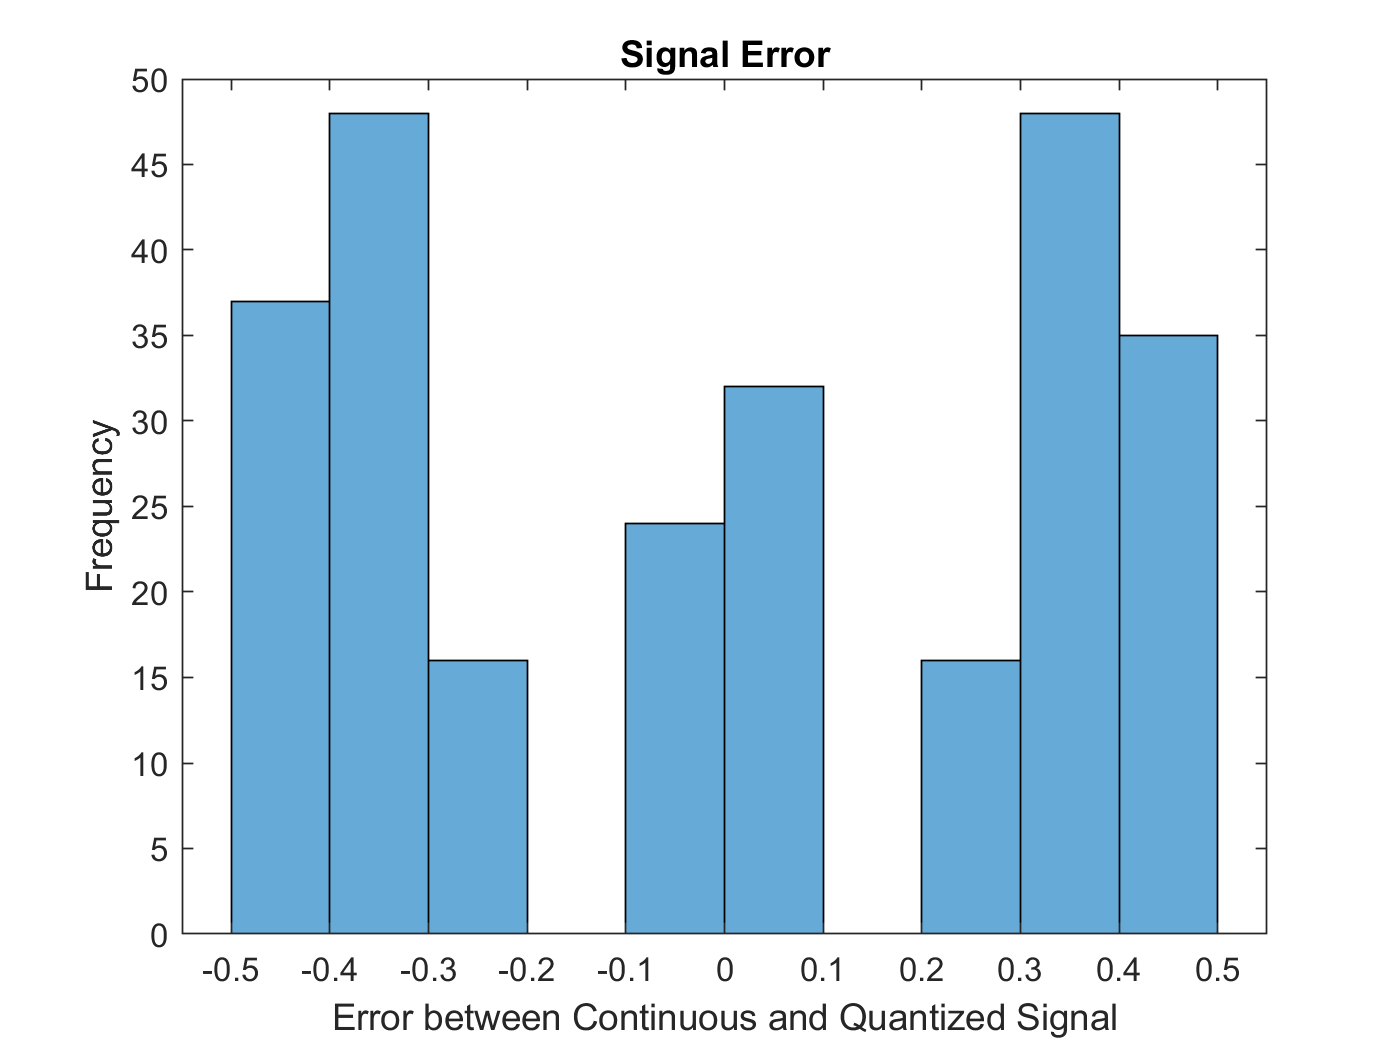

%  Plot the histogram of the quantization error

binEdges = -0.5:0.1:0.5;

%  Solution -- place your code here
histogram(error, -.5:.1:.5)
title('Signal Error')
xlabel('Error between Continuous and Quantized Signal')
ylabel('Frequency')

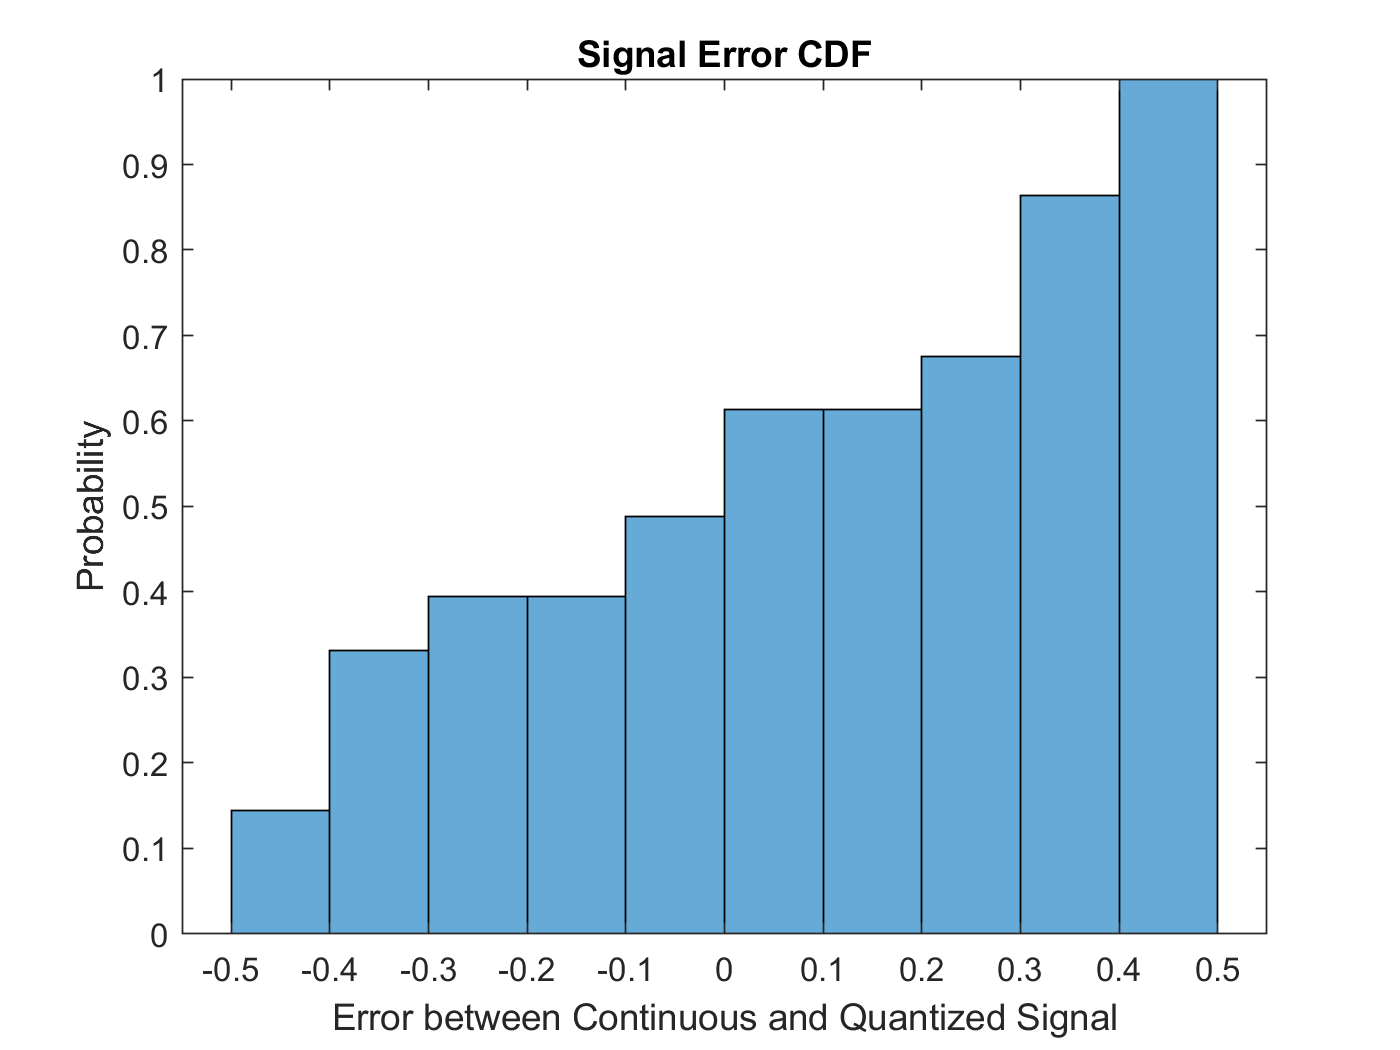

histogram(error, -.5:.1:.5, 'Normalization','cdf')
title('Signal Error CDF')
xlabel('Error between Continuous and Quantized Signal')
ylabel('Probability')

   Press the Button below to Run the code in this section

#### Question 10

How would you describe the distribution of the error of the estimate (normal, uniform, triangular, other)? Explain.

#### Type your answer here:

 The distribution of the error of the estimate is not uniform. There are gaps in between the datapoints.

#### Question 11

Are the distributions of the quantization error significantly different or largely the same between the correlated and the uncorrelated signals? Explain.

#### Type your answer here:

The distributions of the quantization error between the correlated and the uncorrelated signals are significantly different. This is caused by not unform distribution.

When the sample rate and the signal are correlated with one another, the distribution of the quantization error may not look as uniform as it does when the sample and the signal rate are uncorrelated with one another.

# Report Requirements

Save this file after running all of the code and reviewing your output and answers to the questions.  Make sure that you include your team member names at the top of this file as well as that of your your team leader.  Then, EXPORT this file as a WORD document, saving or printing it as a PDF from within WORD.  

Submit your completed MATLAB Live Script file and the PDF to the Assignments section of myCourses for Lab 2.  Review your PDF file before submitting to insure that all your graphs have rendered correctly and all of your questions have been answered completely.  

Also submit a brief WBR - Work Breakdown Report in PDF, DOC or TXT format that describes the contribution of each team member to this lab. 

Finally - Use the following file naming convention with your Lab section and group name. For example: 

Labsect01_GroupName_Lab2.mlx

10 points have been allocated to following the above procedures and guidelines for submission (10% of this assignment grade)